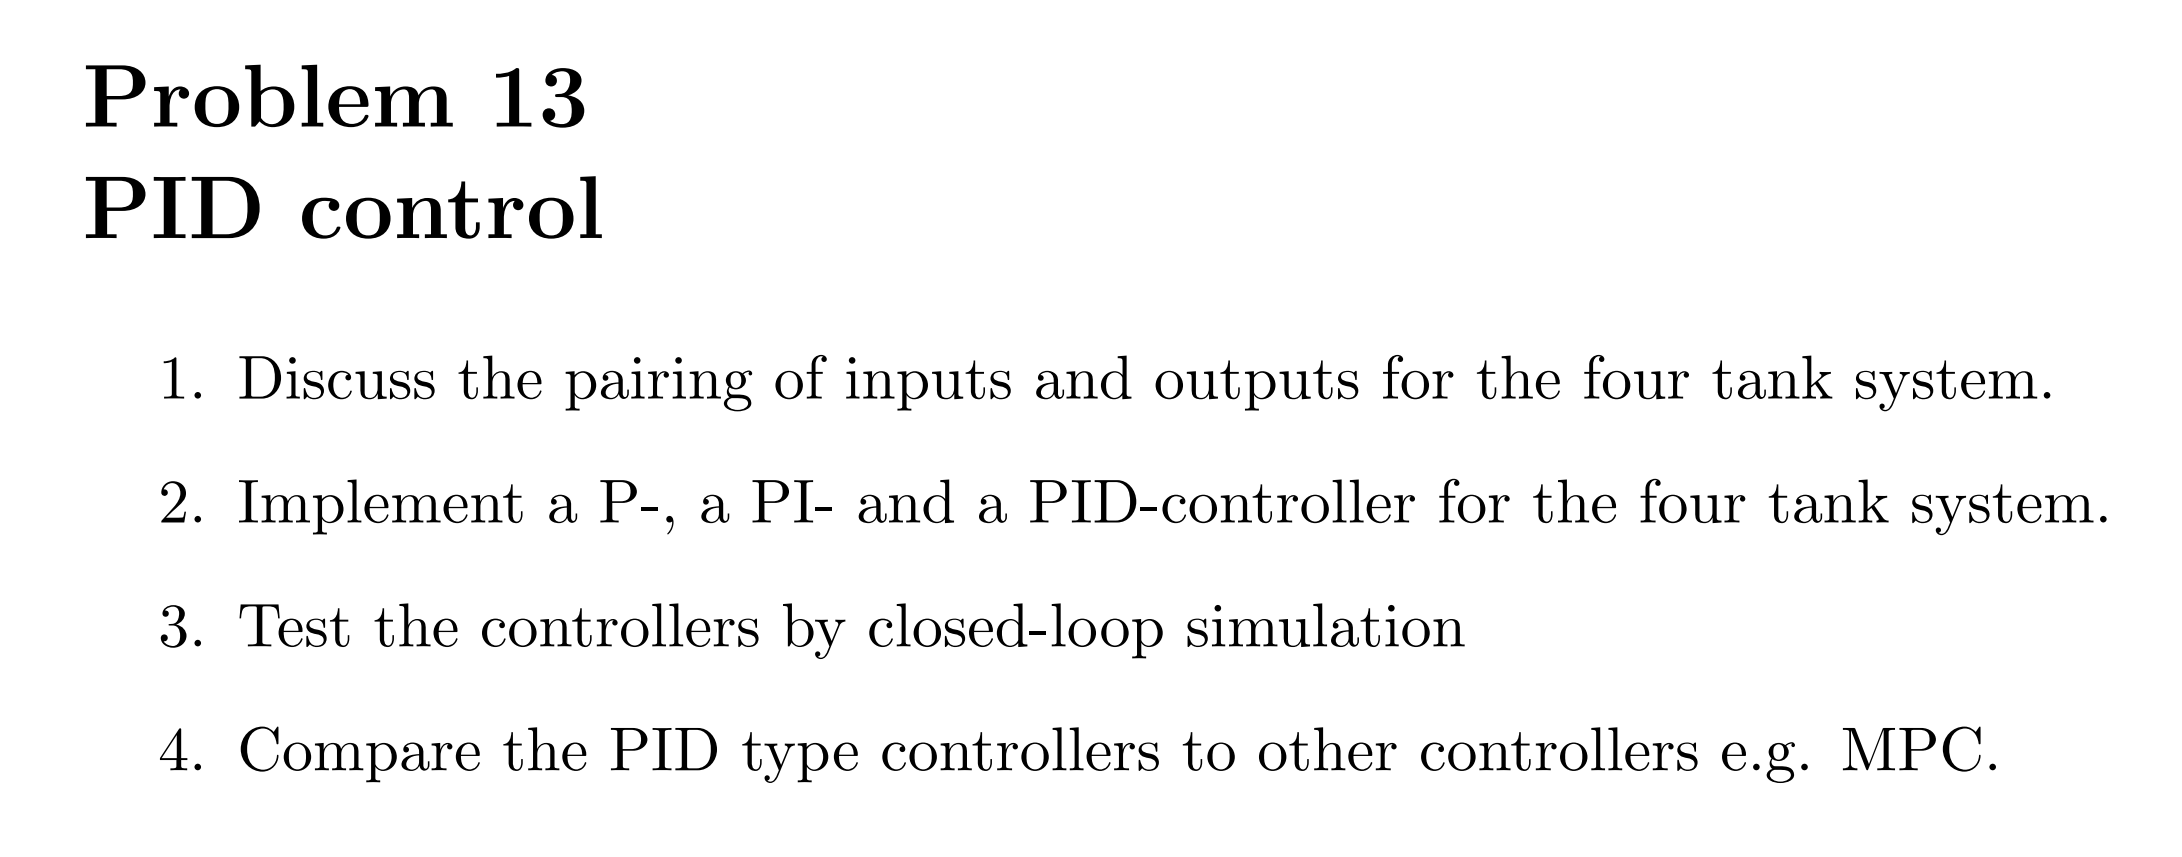

% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3 1.2272

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3 380

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1 0.45
gamma2 = 0.40; % Flow distribution constant. Valve 2 0.40
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------
%a3 a4:1.2272 Non-minimum phase system
%a3 a4:8 Minimum phase system

%steady-state
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F3;F4]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.1068
    3.6822
    2.3787
    2.2157


ys = FourTankSystemSensor(xs,p)

ys =   108.0357
   96.8675
   62.5759
   58.2863


zs = FourTankSystemOutput(xs,p)

zs =   108.0357
   96.8675


syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))

Ass =    -0.0069         0    0.0090         0
         0   -0.0073         0    0.0094
         0         0   -0.0090         0
         0         0         0   -0.0094


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Czss=Css(1:2,:)

Czss =     0.0026         0         0         0
         0    0.0026         0         0


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))

Dss =      0     0
     0     0
     0     0
     0     0


Dzss=Dss(1:2,:)

Dzss =      0     0
     0     0


%Compute discrete-time state space models
Ts = 4; 
[Ad,Bd]=c2dzoh(Ass,Bss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd =     1.7755    0.0425
    0.0403    1.5770
         0    2.3571
    2.1593         0


[Ad,Bd_d]=c2dzoh(Ass,Bdss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd_d =     0.0708         0
         0    0.0733
    3.9286         0
         0    3.9260


Gw_d=Bd_d;

%Compute the transfer function
[num_c_F1,den_c_F1]=ss2tf(Ass,Bss,Css,Dss,1);
[num_c_F2,den_c_F2]=ss2tf(Ass,Bss,Css,Dss,2);
G_c_F1_y1=tf(num_c_F1(1,:),den_c_F1);%same to con->dis
G_c_F1_y2=tf(num_c_F1(2,:),den_c_F1);
G_c_F2_y1=tf(num_c_F2(1,:),den_c_F2);
G_c_F2_y2=tf(num_c_F2(2,:),den_c_F2);

[num_d_F1,den_d_F1]=ss2tf(Ad,Bd,Css,Dss,1);
[num_d_F2,den_d_F2]=ss2tf(Ad,Bd,Css,Dss,2);
G_d_F1_y1=tf(num_d_F1(1,:),den_d_F1,Ts);%same to con->dis
G_d_F1_y2=tf(num_d_F1(2,:),den_d_F1,Ts);
G_d_F2_y1=tf(num_d_F2(1,:),den_d_F2,Ts);
G_d_F2_y2=tf(num_d_F2(2,:),den_d_F2,Ts);

G_MIMO=[G_d_F1_y1,G_d_F1_y2;G_d_F2_y1,G_d_F2_y2];
G_c_MIMO=[G_c_F1_y1,G_c_F1_y2;G_c_F2_y1,G_c_F2_y2];

%steady decoupling matrix
G0_MIMO=dcgain(G_MIMO);
G0_c_11=dcgain(cell2mat(G_c_F1_y1.Numerator),cell2mat(G_c_F1_y1.Denominator))

G0_c_11 = 0.1721

G0_c_12=dcgain(cell2mat(G_c_F1_y2.Numerator),cell2mat(G_c_F1_y2.Denominator))

G0_c_12 = 0.1992

G0_c_21=dcgain(cell2mat(G_c_F2_y1.Numerator),cell2mat(G_c_F2_y1.Denominator))

G0_c_21 = 0.2295

G0_c_22=dcgain(cell2mat(G_c_F2_y2.Numerator),cell2mat(G_c_F2_y2.Denominator))

G0_c_22 = 0.1449

G0_c_MIMO=dcgain(G_c_MIMO);%just for test

%Compute RGA
F0=G0_MIMO(1,2)*G0_MIMO(2,1)/(G0_MIMO(1,1)*G0_MIMO(2,2))

F0 = 1.8333

T0_11=1/(1-F0)

T0_11 = -1.2000

T0_12=-F0/(1-F0)

T0_12 = 2.2000

T0_21=-F0/(1-F0)

T0_21 = 2.2000

T0_22=1/(1-F0)

T0_22 = -1.2000

%Compute steady decoupling matrix
G0_11=G0_MIMO(1,1);
G0_12=G0_MIMO(1,2);
G0_21=G0_MIMO(2,1);
G0_22=G0_MIMO(2,2);
D0=(1/(G0_11*G0_22-G0_12*G0_21))*[-G0_12*G0_21,G0_22*G0_12;G0_11*G0_21,-G0_21*G0_12]

D0 =     2.2000   -1.3887
   -1.9010    2.2000


%TEST of decoupling matrix
G_MIMO_decop=D0*G_MIMO

G_MIMO_decop =
 
  From input 1 to output...
       0.01012 z^7 - 0.06883 z^6 + 0.2006 z^5 - 0.3248 z^4 + 0.3156 z^3 - 0.184 z^2 + 0.05957 z - 0.008267
   1:  ---------------------------------------------------------------------------------------------------
          z^8 - 7.744 z^7 + 26.24 z^6 - 50.79 z^5 + 61.46 z^4 - 47.59 z^3 + 23.03 z^2 - 6.37 z + 0.7708
 
       -0.008634 z^7 + 0.05894 z^6 - 0.1724 z^5 + 0.2802 z^4 - 0.2732 z^3 + 0.1598 z^2 - 0.05194 z + 0.007233
   2:  ------------------------------------------------------------------------------------------------------
           z^8 - 7.744 z^7 + 26.24 z^6 - 50.79 z^5 + 61.46 z^4 - 47.59 z^3 + 23.03 z^2 - 6.37 z + 0.7708
 
  From input 2 to output...
       -0.005529 z^7 + 0.0379 z^6 - 0.1113 z^5 + 0.1816 z^4 - 0.1778 z^3 + 0.1044 z^2 - 0.03405 z + 0.00476
   1:  ----------------------------------------------------------------------------------------------------
          z^8 - 7.744 z^7 + 26.24 z^6 - 50.79 z^5 + 61.46 z^4 - 

G0_MIMO_decop=dcgain(G_MIMO_decop)

G0_MIMO_decop =     0.0597    0.2359
    0.1768   -0.0596


F0_decop=G0_MIMO_decop(1,2)*G0_MIMO_decop(2,1)/(G0_MIMO_decop(1,1)*G0_MIMO_decop(2,2))

F0_decop = -11.7107

T0_11_decop=1/(1-F0_decop)

T0_11_decop = 0.0787

T0_12_decop=-F0_decop/(1-F0_decop)

T0_12_decop = 0.9213

T0_21_decop=-F0_decop/(1-F0_decop)

T0_21_decop = 0.9213

T0_22_decop=1/(1-F0_decop)

T0_22_decop = 0.0787

%PID in linear model without step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
d = [repmat(50,1,N); repmat(50,1,N)];
%d(1,index_step:end)=100;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);

x0=zeros(4,1);
d0=zeros(2,1);
x(:,1) = x0;
u(:,1) = zeros(2,1);
ref=80;

%PID
u_min=0;
u_max=1000;
uk=zeros(num_u,1);
xk=x0;
yk=Css*xk+Dss*uk+v_low(:,1); % Sensor function
yk_old=yk;
Ik=0;
KP=2.2715;
KI=0.012046;
KD=4.4948;
decop=[0.0787,0.9213;0.9213,0.0787];
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%
yk=Css*xk+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;

%%%%%%%%%%%%%%%PID controller%%%%%%%%%%%%%% 
tic;
[uk,Ik] = MIMOPID(0,ref,yk(1:2),yk_old(1:2),Ik,KP,KI,KD,Ts,u_min,u_max,decop);
elapsedTime = toc;
t_record=[t_record;elapsedTime];
yk_old=yk;
%state update
xk=Ad*x(:,k)+Bd*uk+Bd_d*d(:,k)+Gw_d*w(:,k);


x(:,k+1)=xk;
u(:,k+1)=uk;
end
k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;


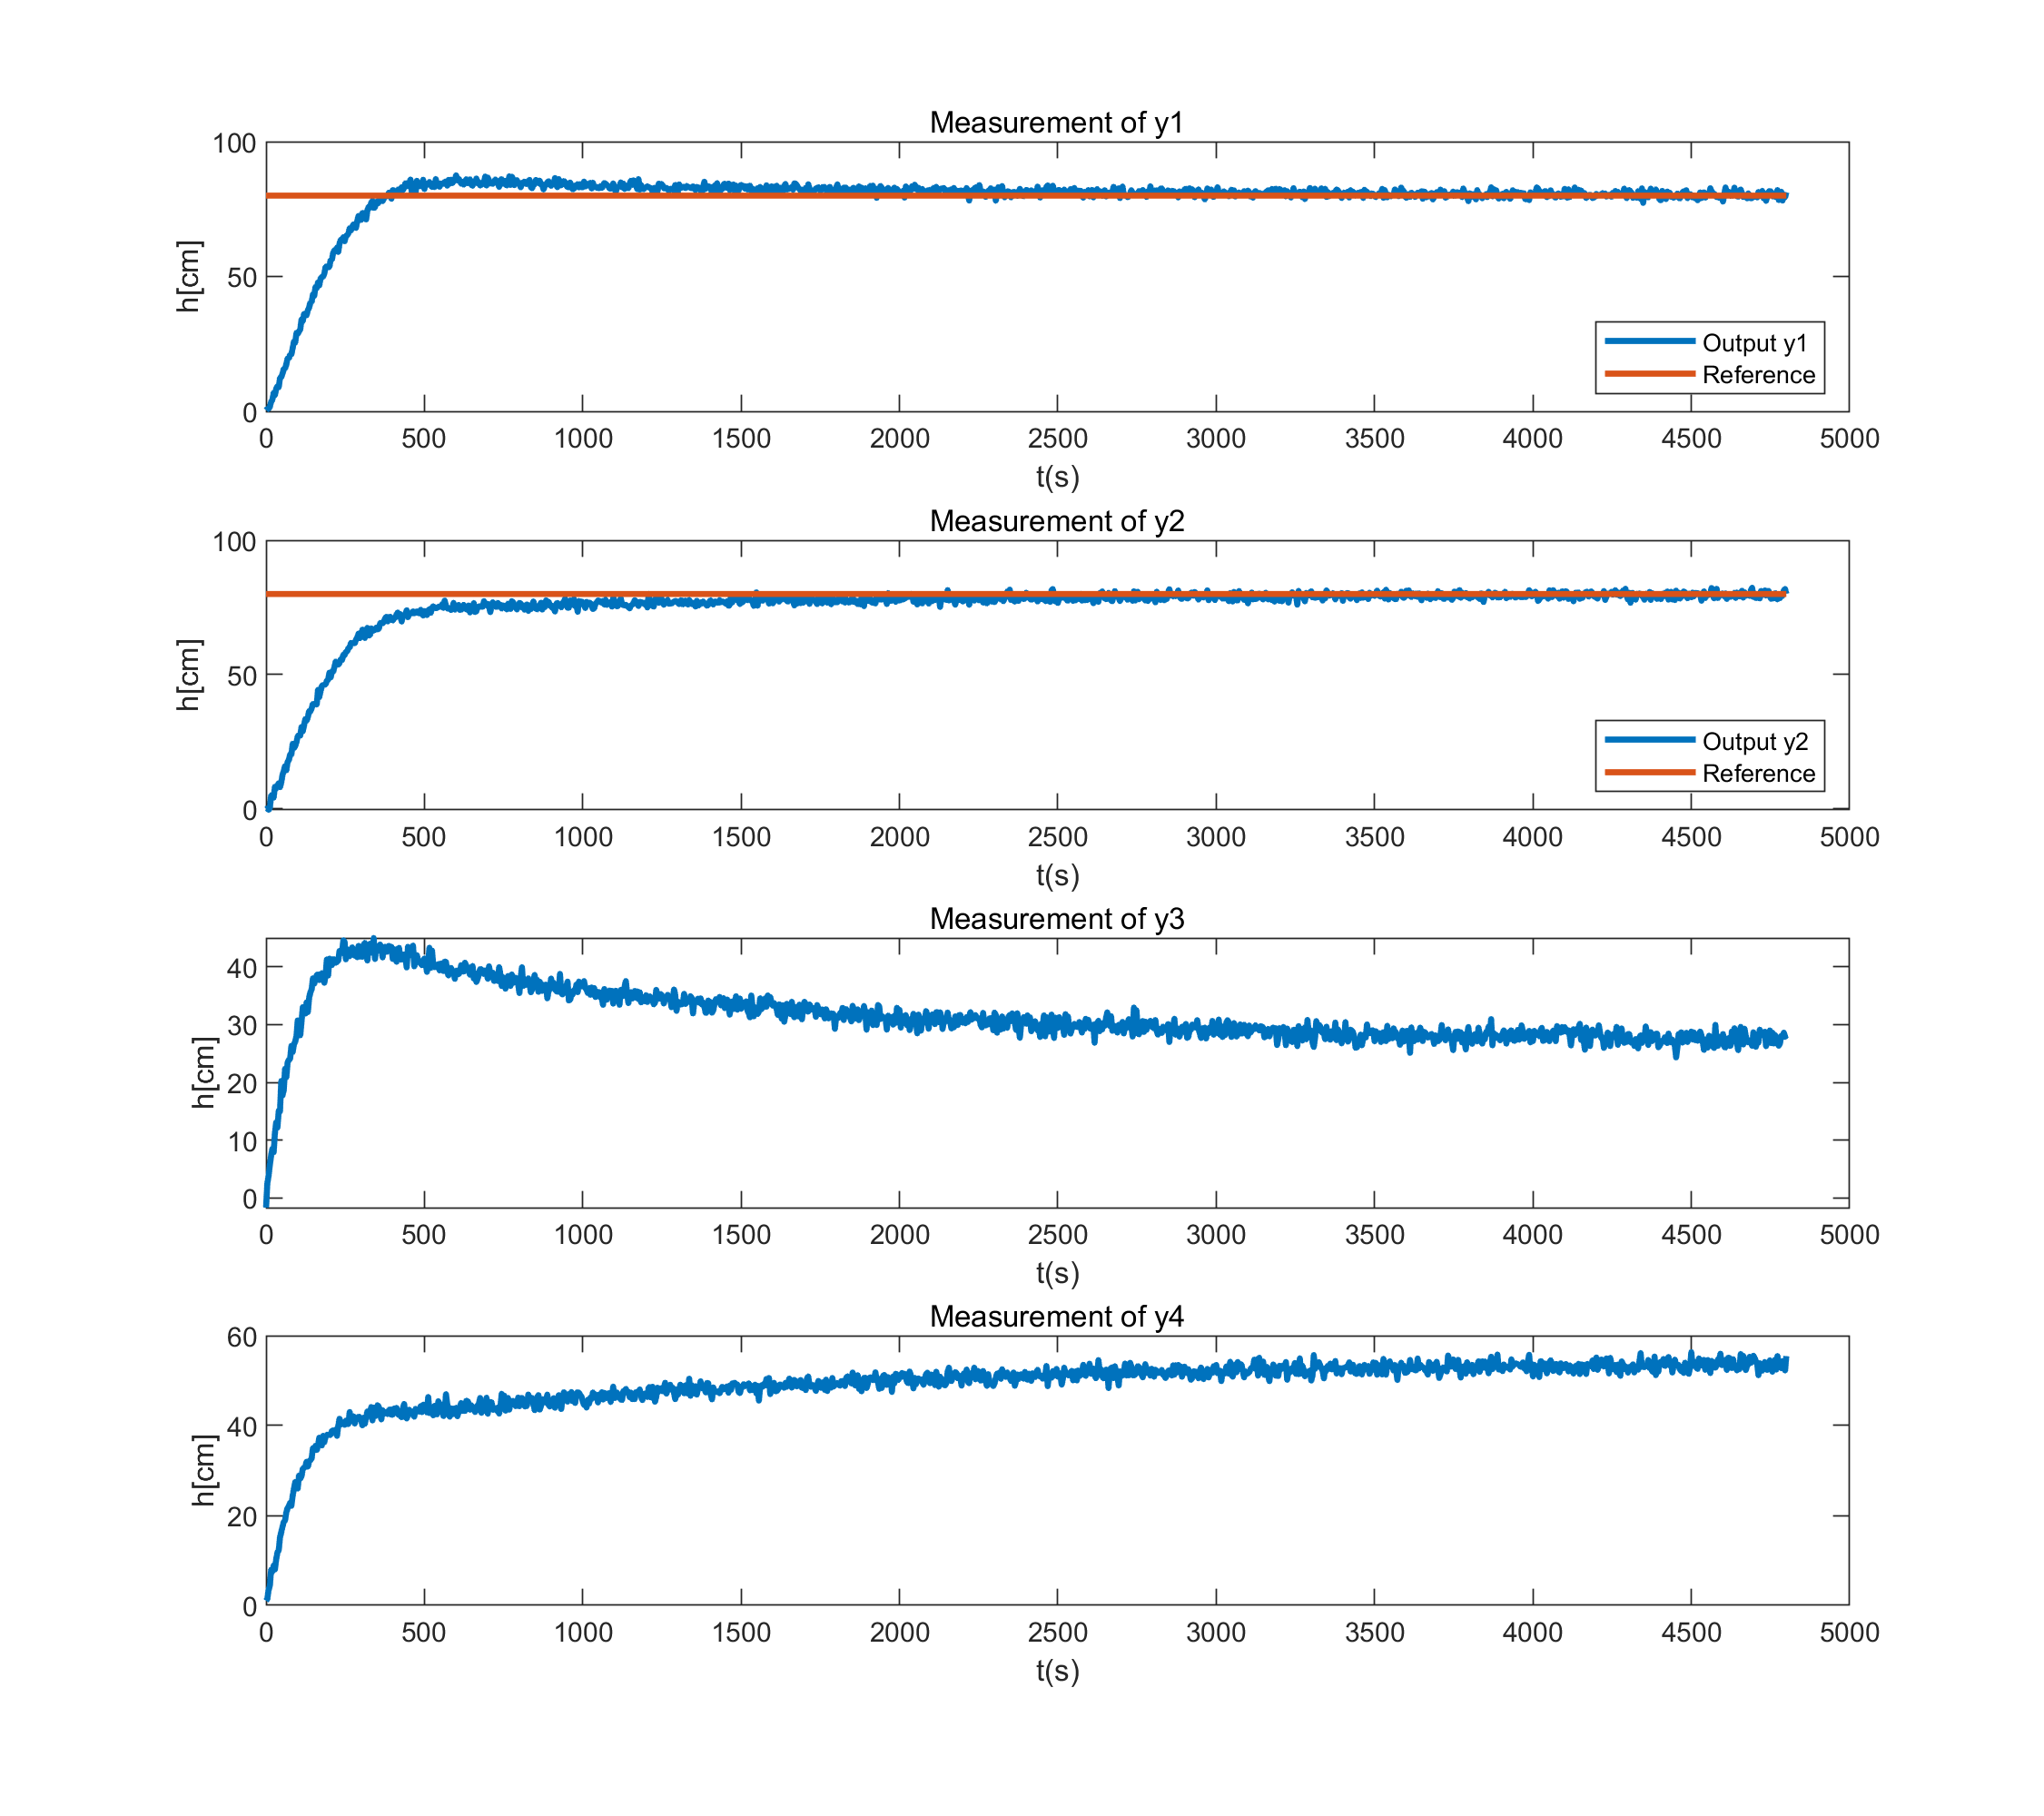

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');

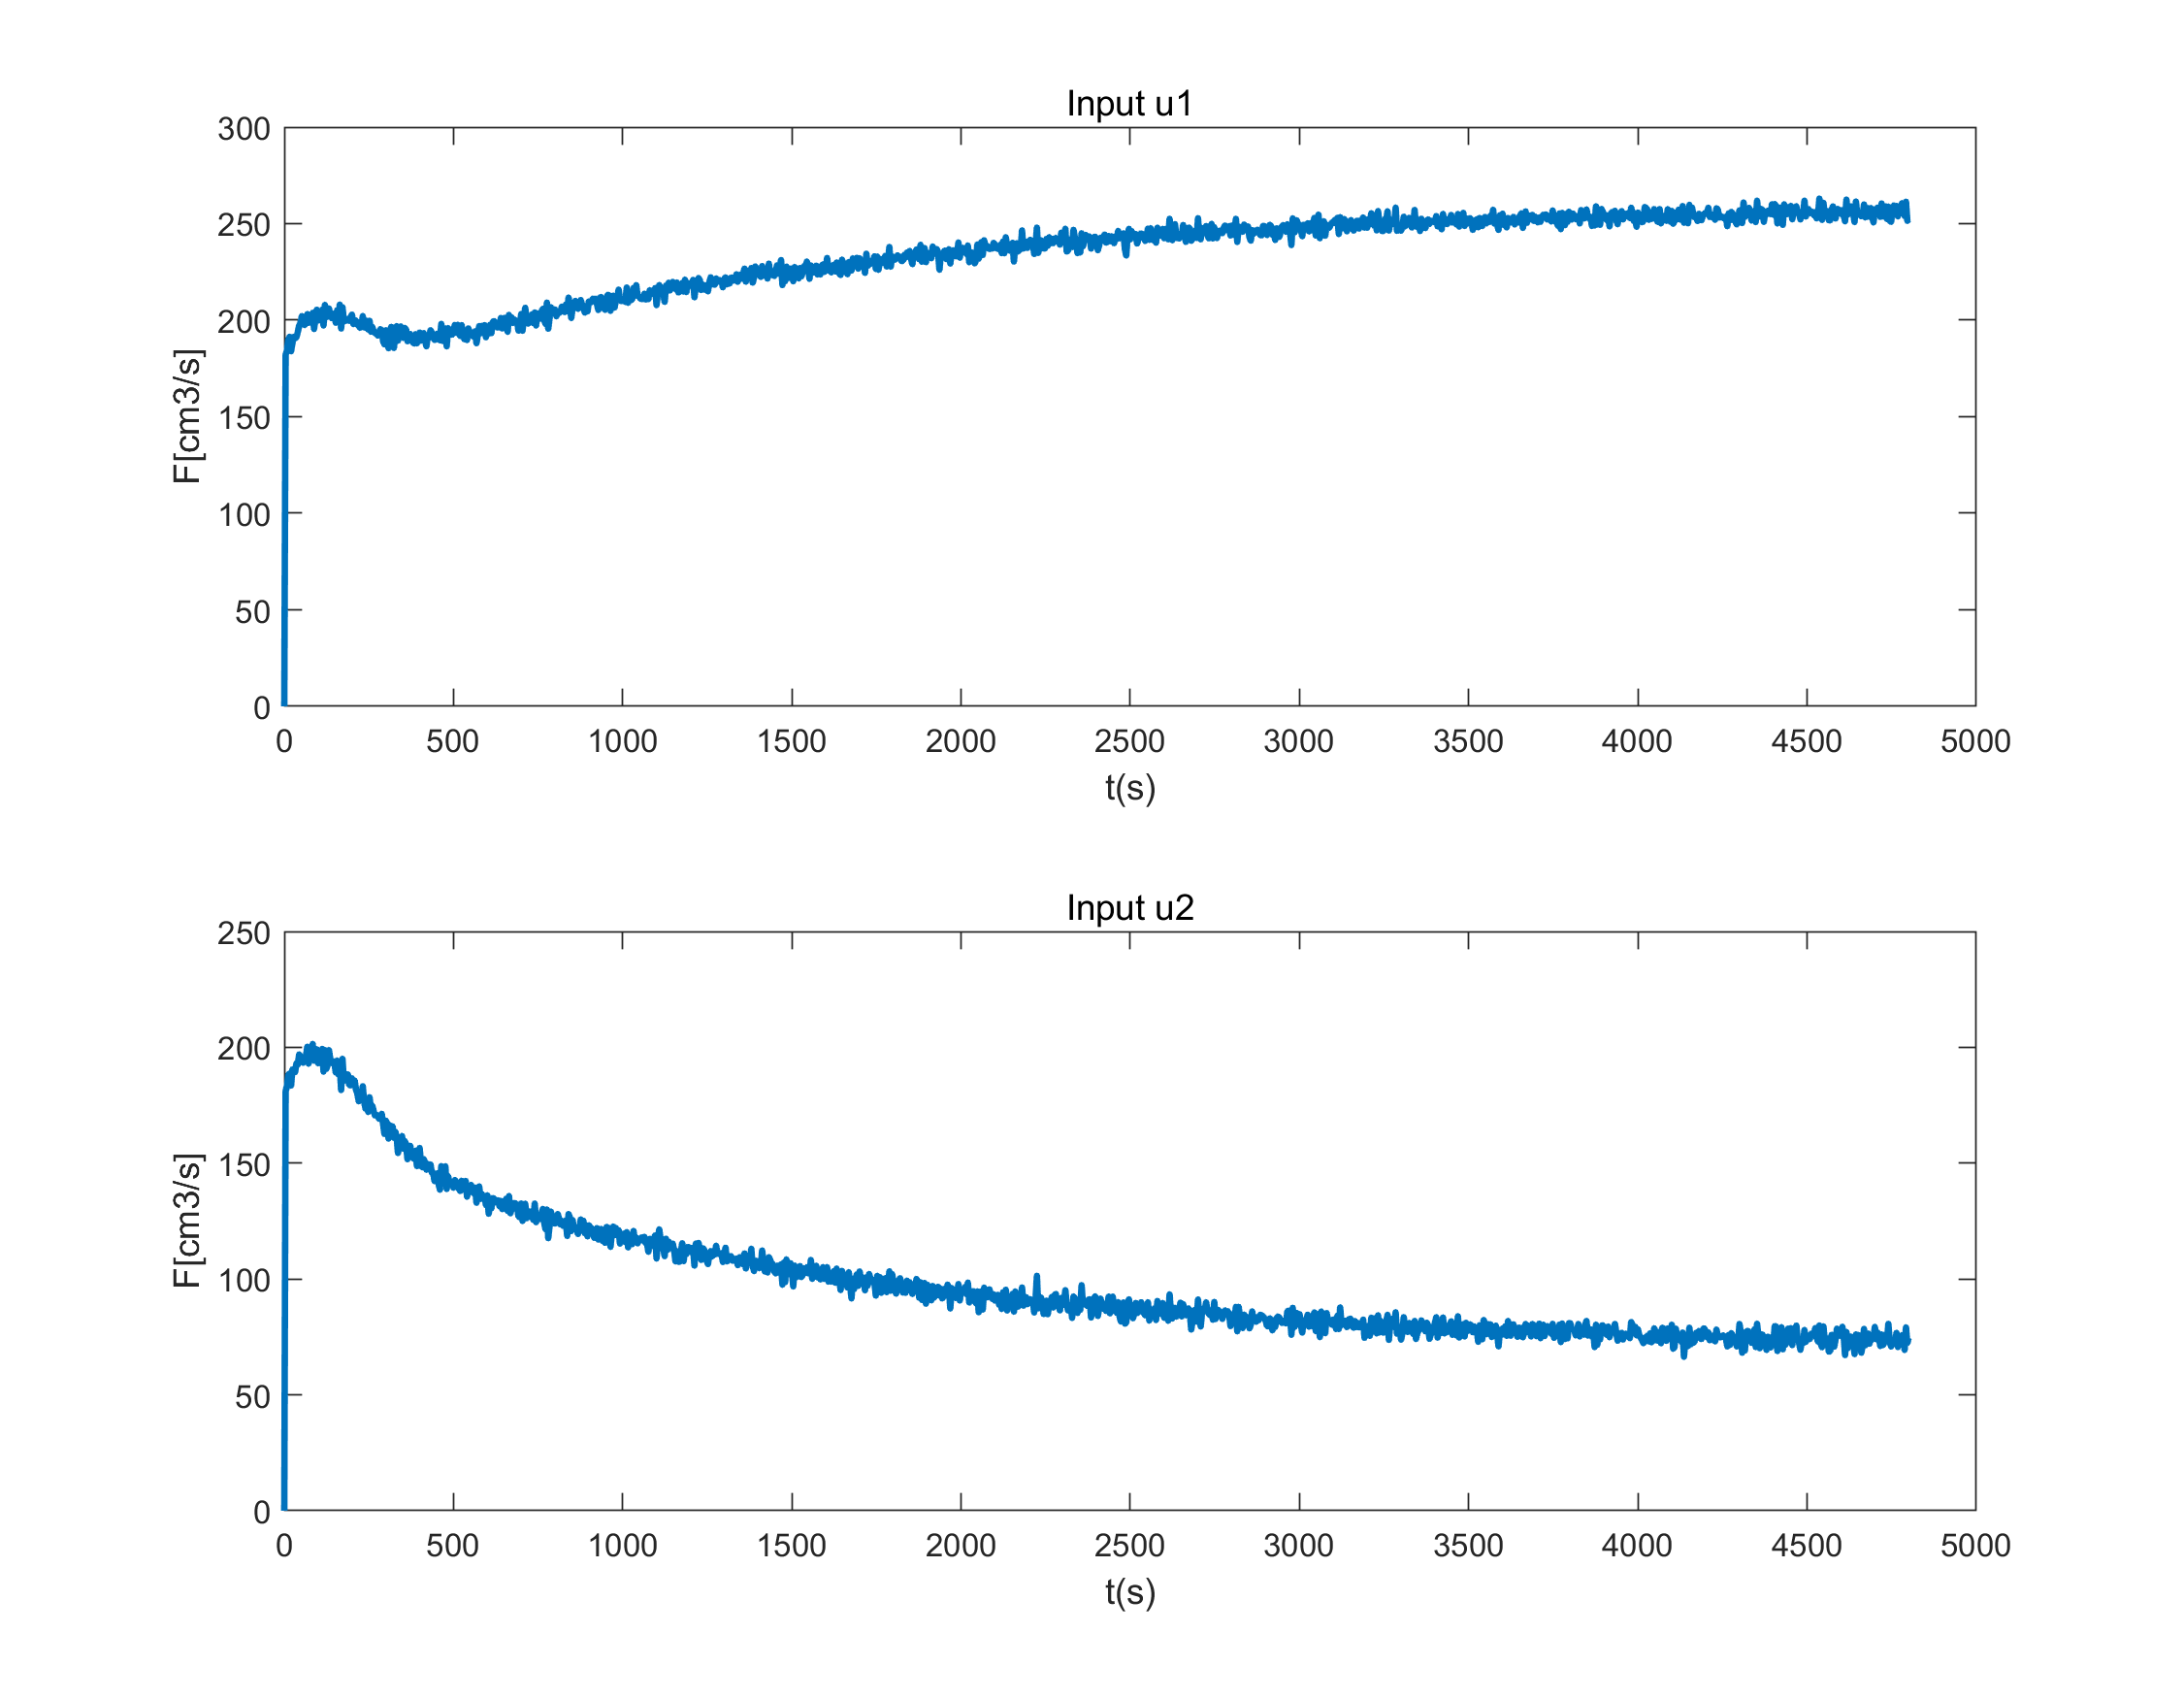

% ylim([0,20]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');

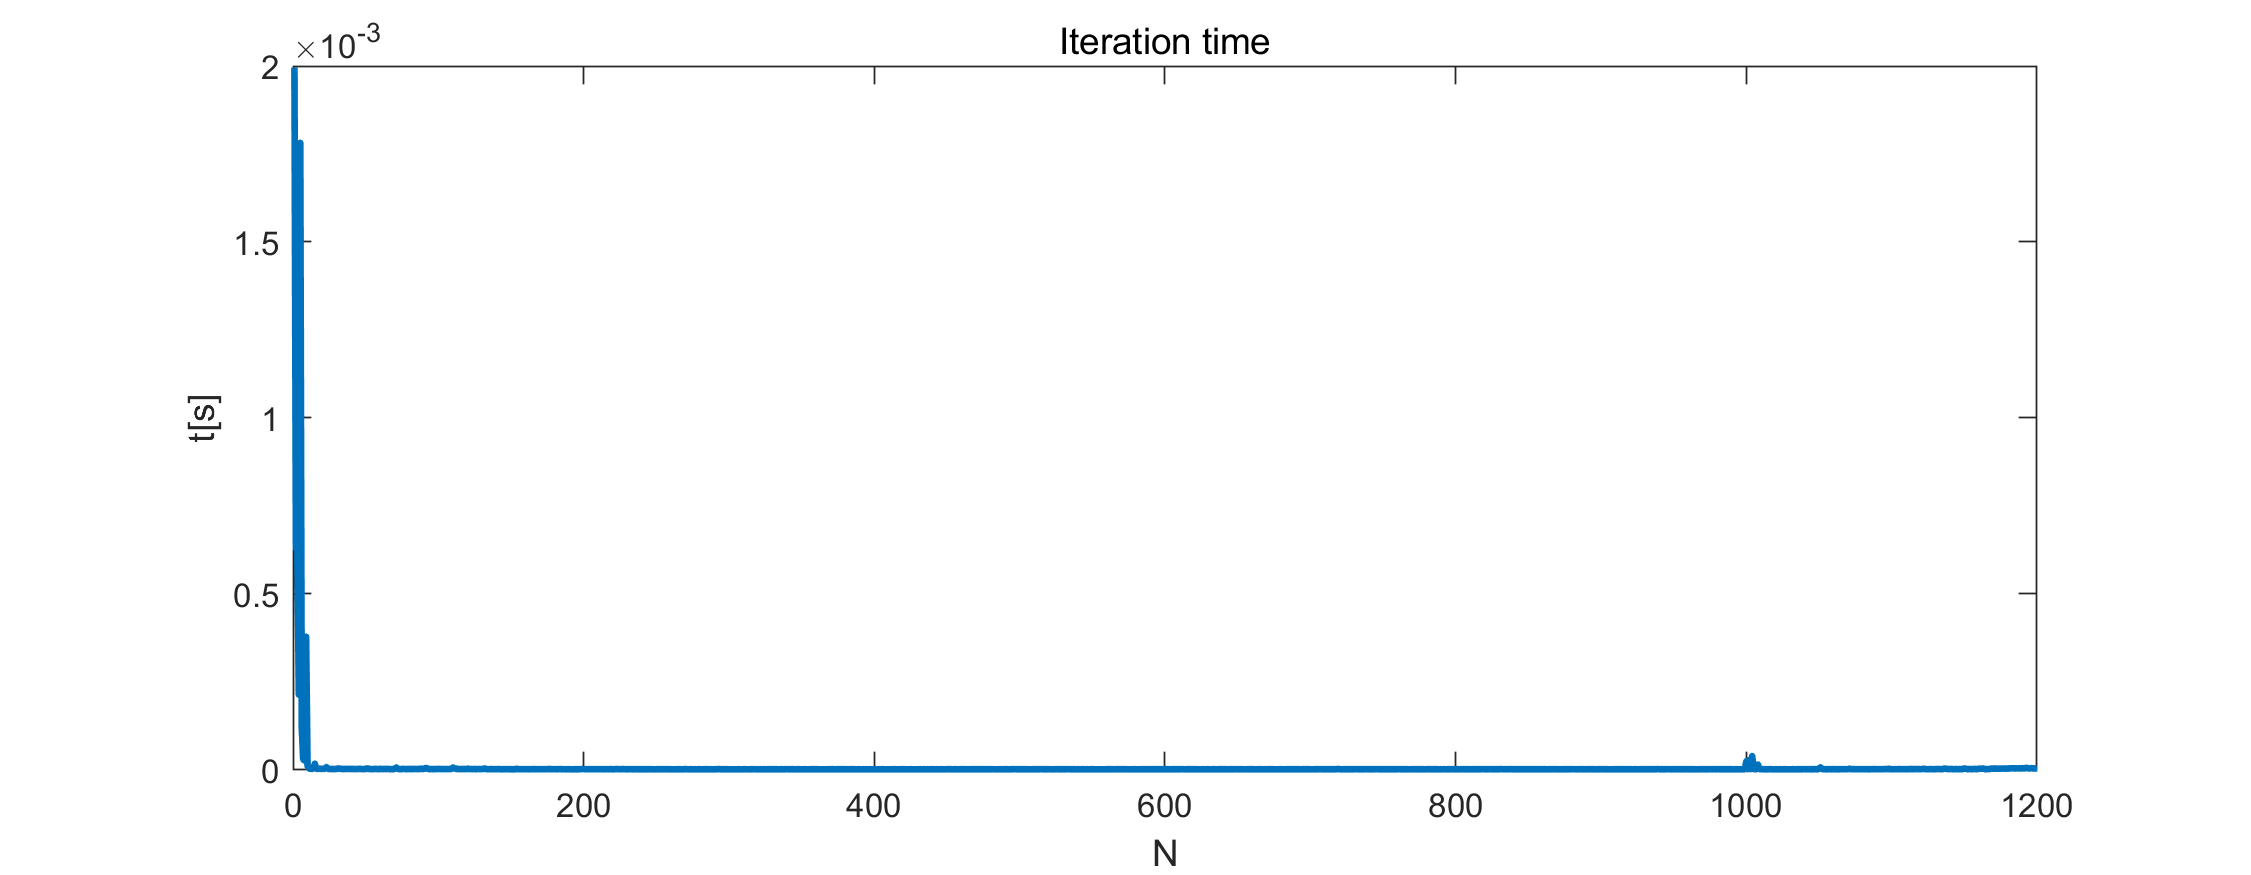

%ylim([0,40]);

figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');

%PID in linear model with step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
d = [repmat(50,1,N); repmat(50,1,N)];
d(1,index_step:end)=100;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);

x0=zeros(4,1);
d0=zeros(2,1);
x(:,1) = x0;
u(:,1) = zeros(2,1);
ref=80;

%PID
u_min=0;
u_max=1000;
uk=zeros(num_u,1);
xk=x0;
yk=Css*xk+Dss*uk+v_low(:,1); % Sensor function
yk_old=yk;
Ik=0;
KP=2.2715;
KI=0.012046;
KD=4.4948;
decop=[0.0787,0.9213;0.9213,0.0787];
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%
yk=Css*xk+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;

%%%%%%%%%%%%%%%PID controller%%%%%%%%%%%%%% 
tic;
[uk,Ik] = MIMOPID(0,ref,yk(1:2),yk_old(1:2),Ik,KP,KI,KD,Ts,u_min,u_max,decop);
elapsedTime = toc;
t_record=[t_record;elapsedTime];
yk_old=yk;
%state update
xk=Ad*x(:,k)+Bd*uk+Bd_d*d(:,k)+Gw_d*w(:,k);


x(:,k+1)=xk;
u(:,k+1)=uk;
end
k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;


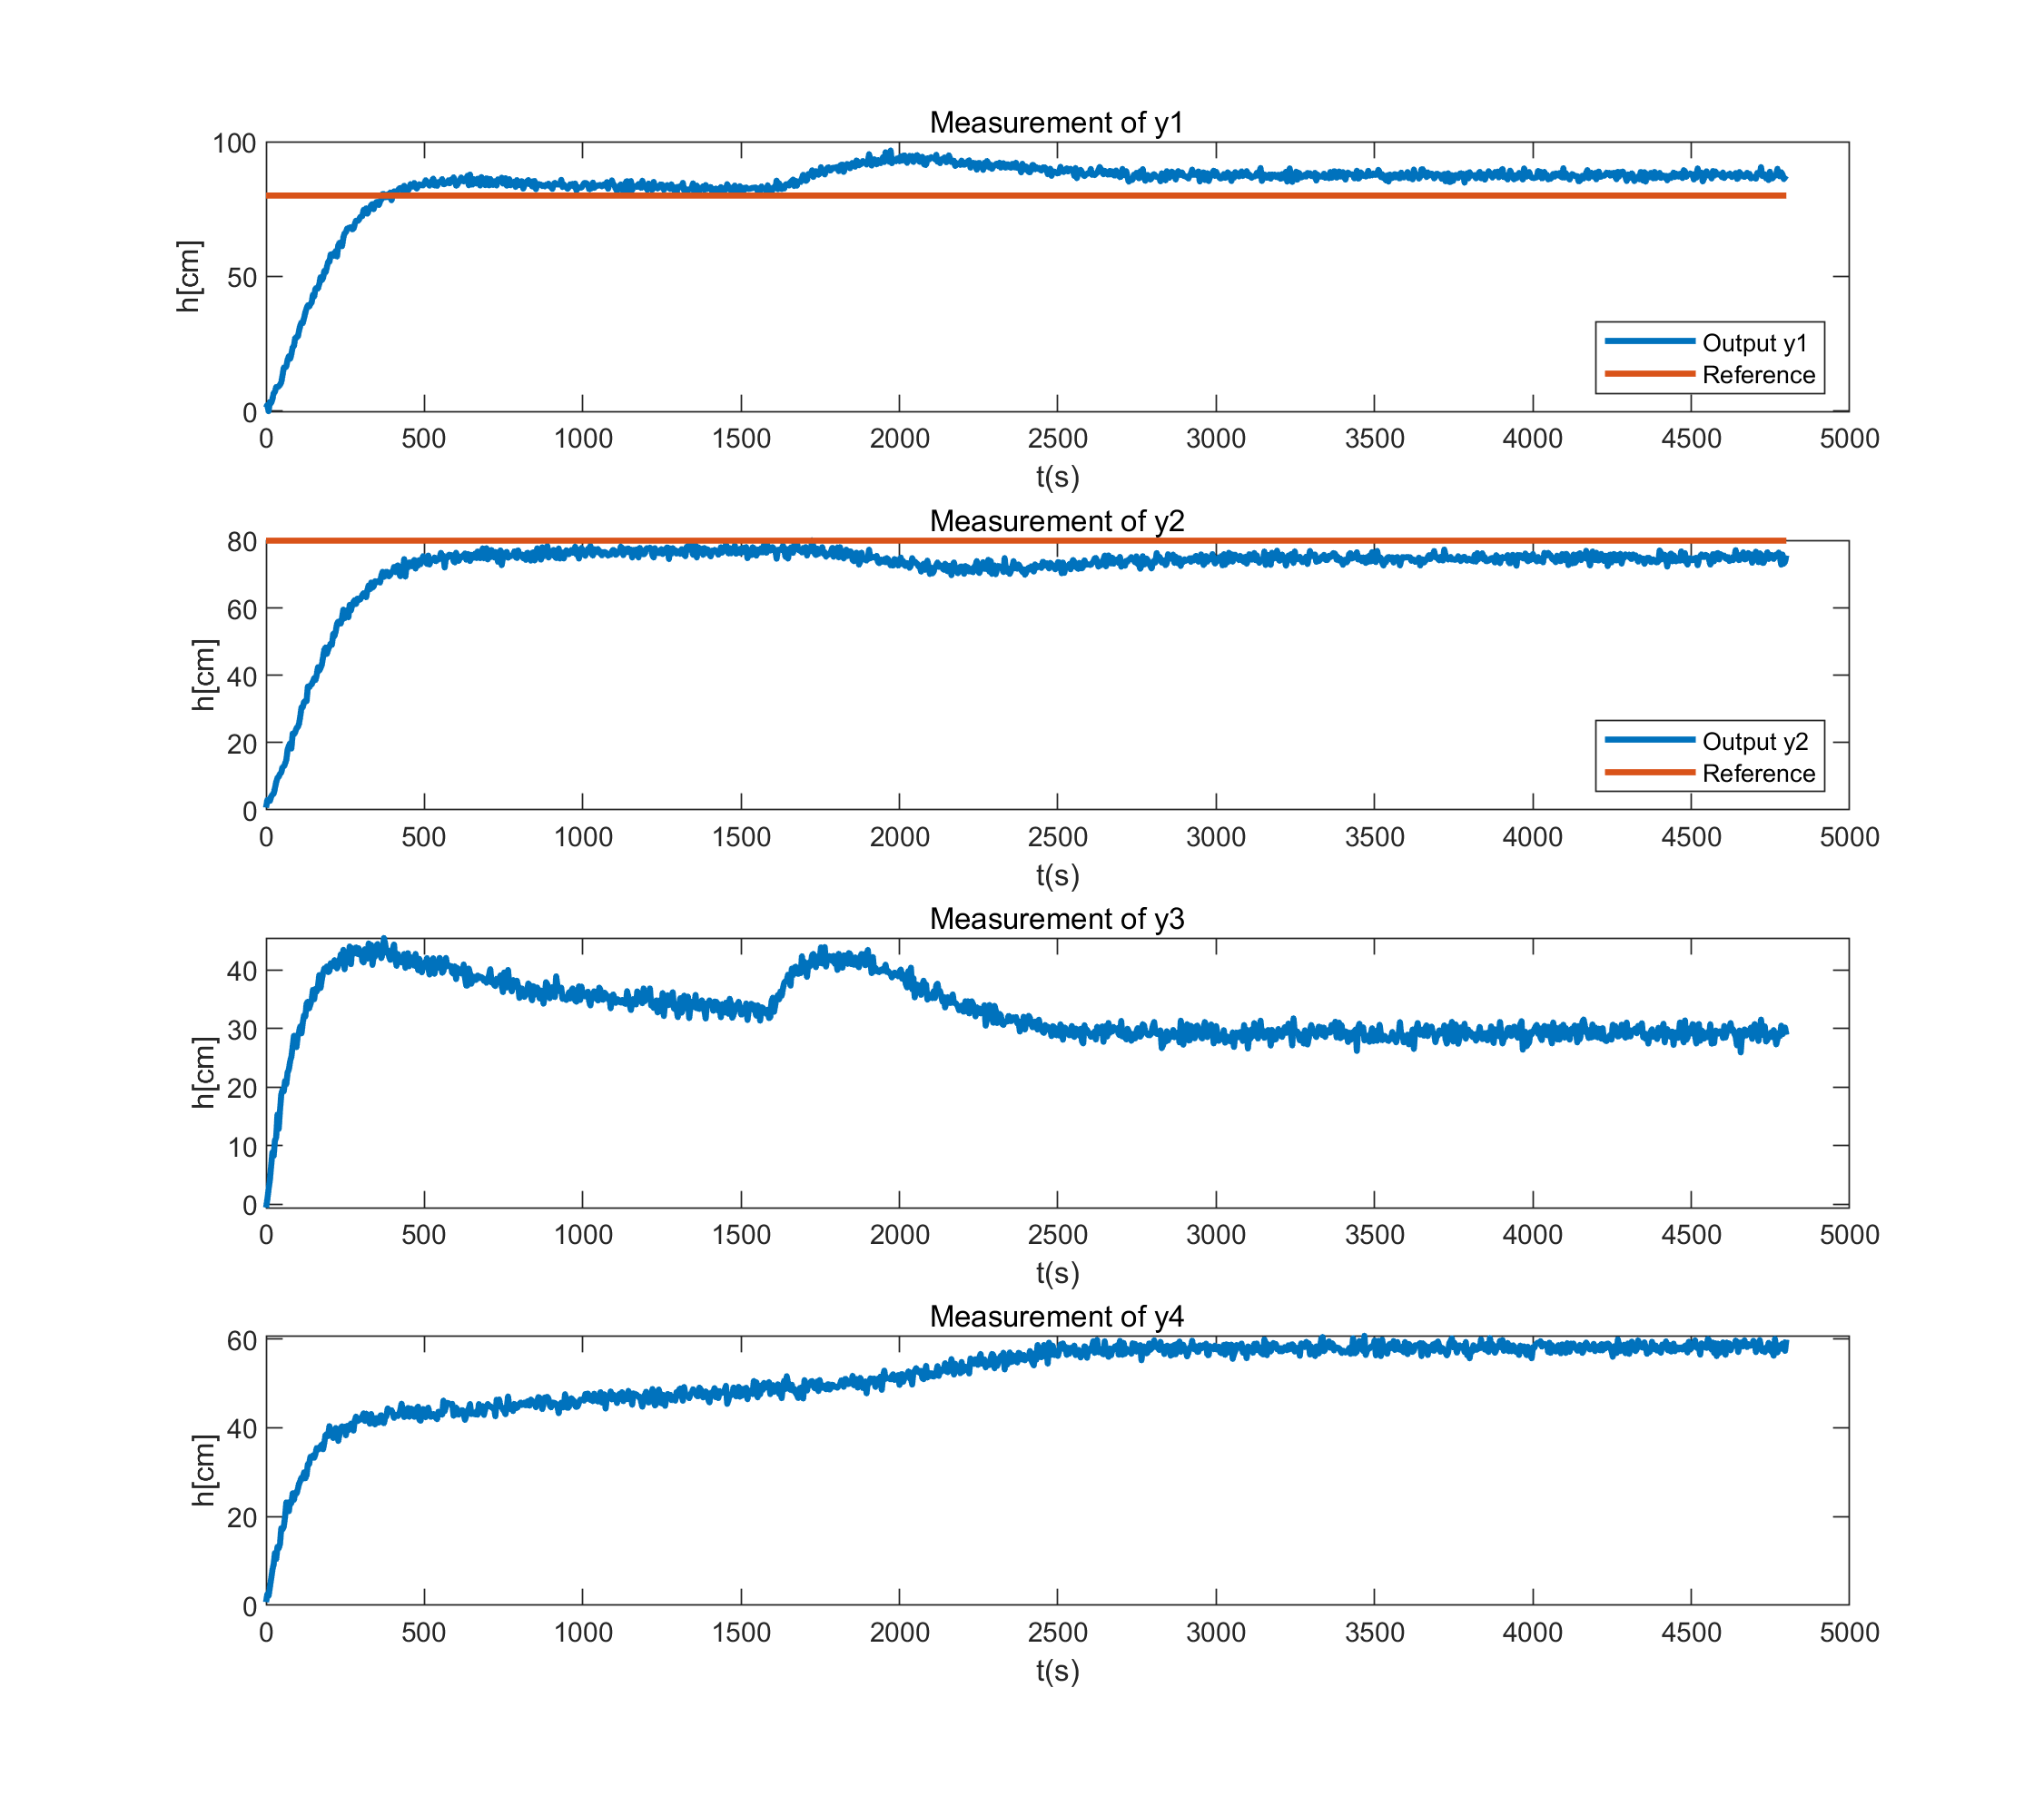

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');

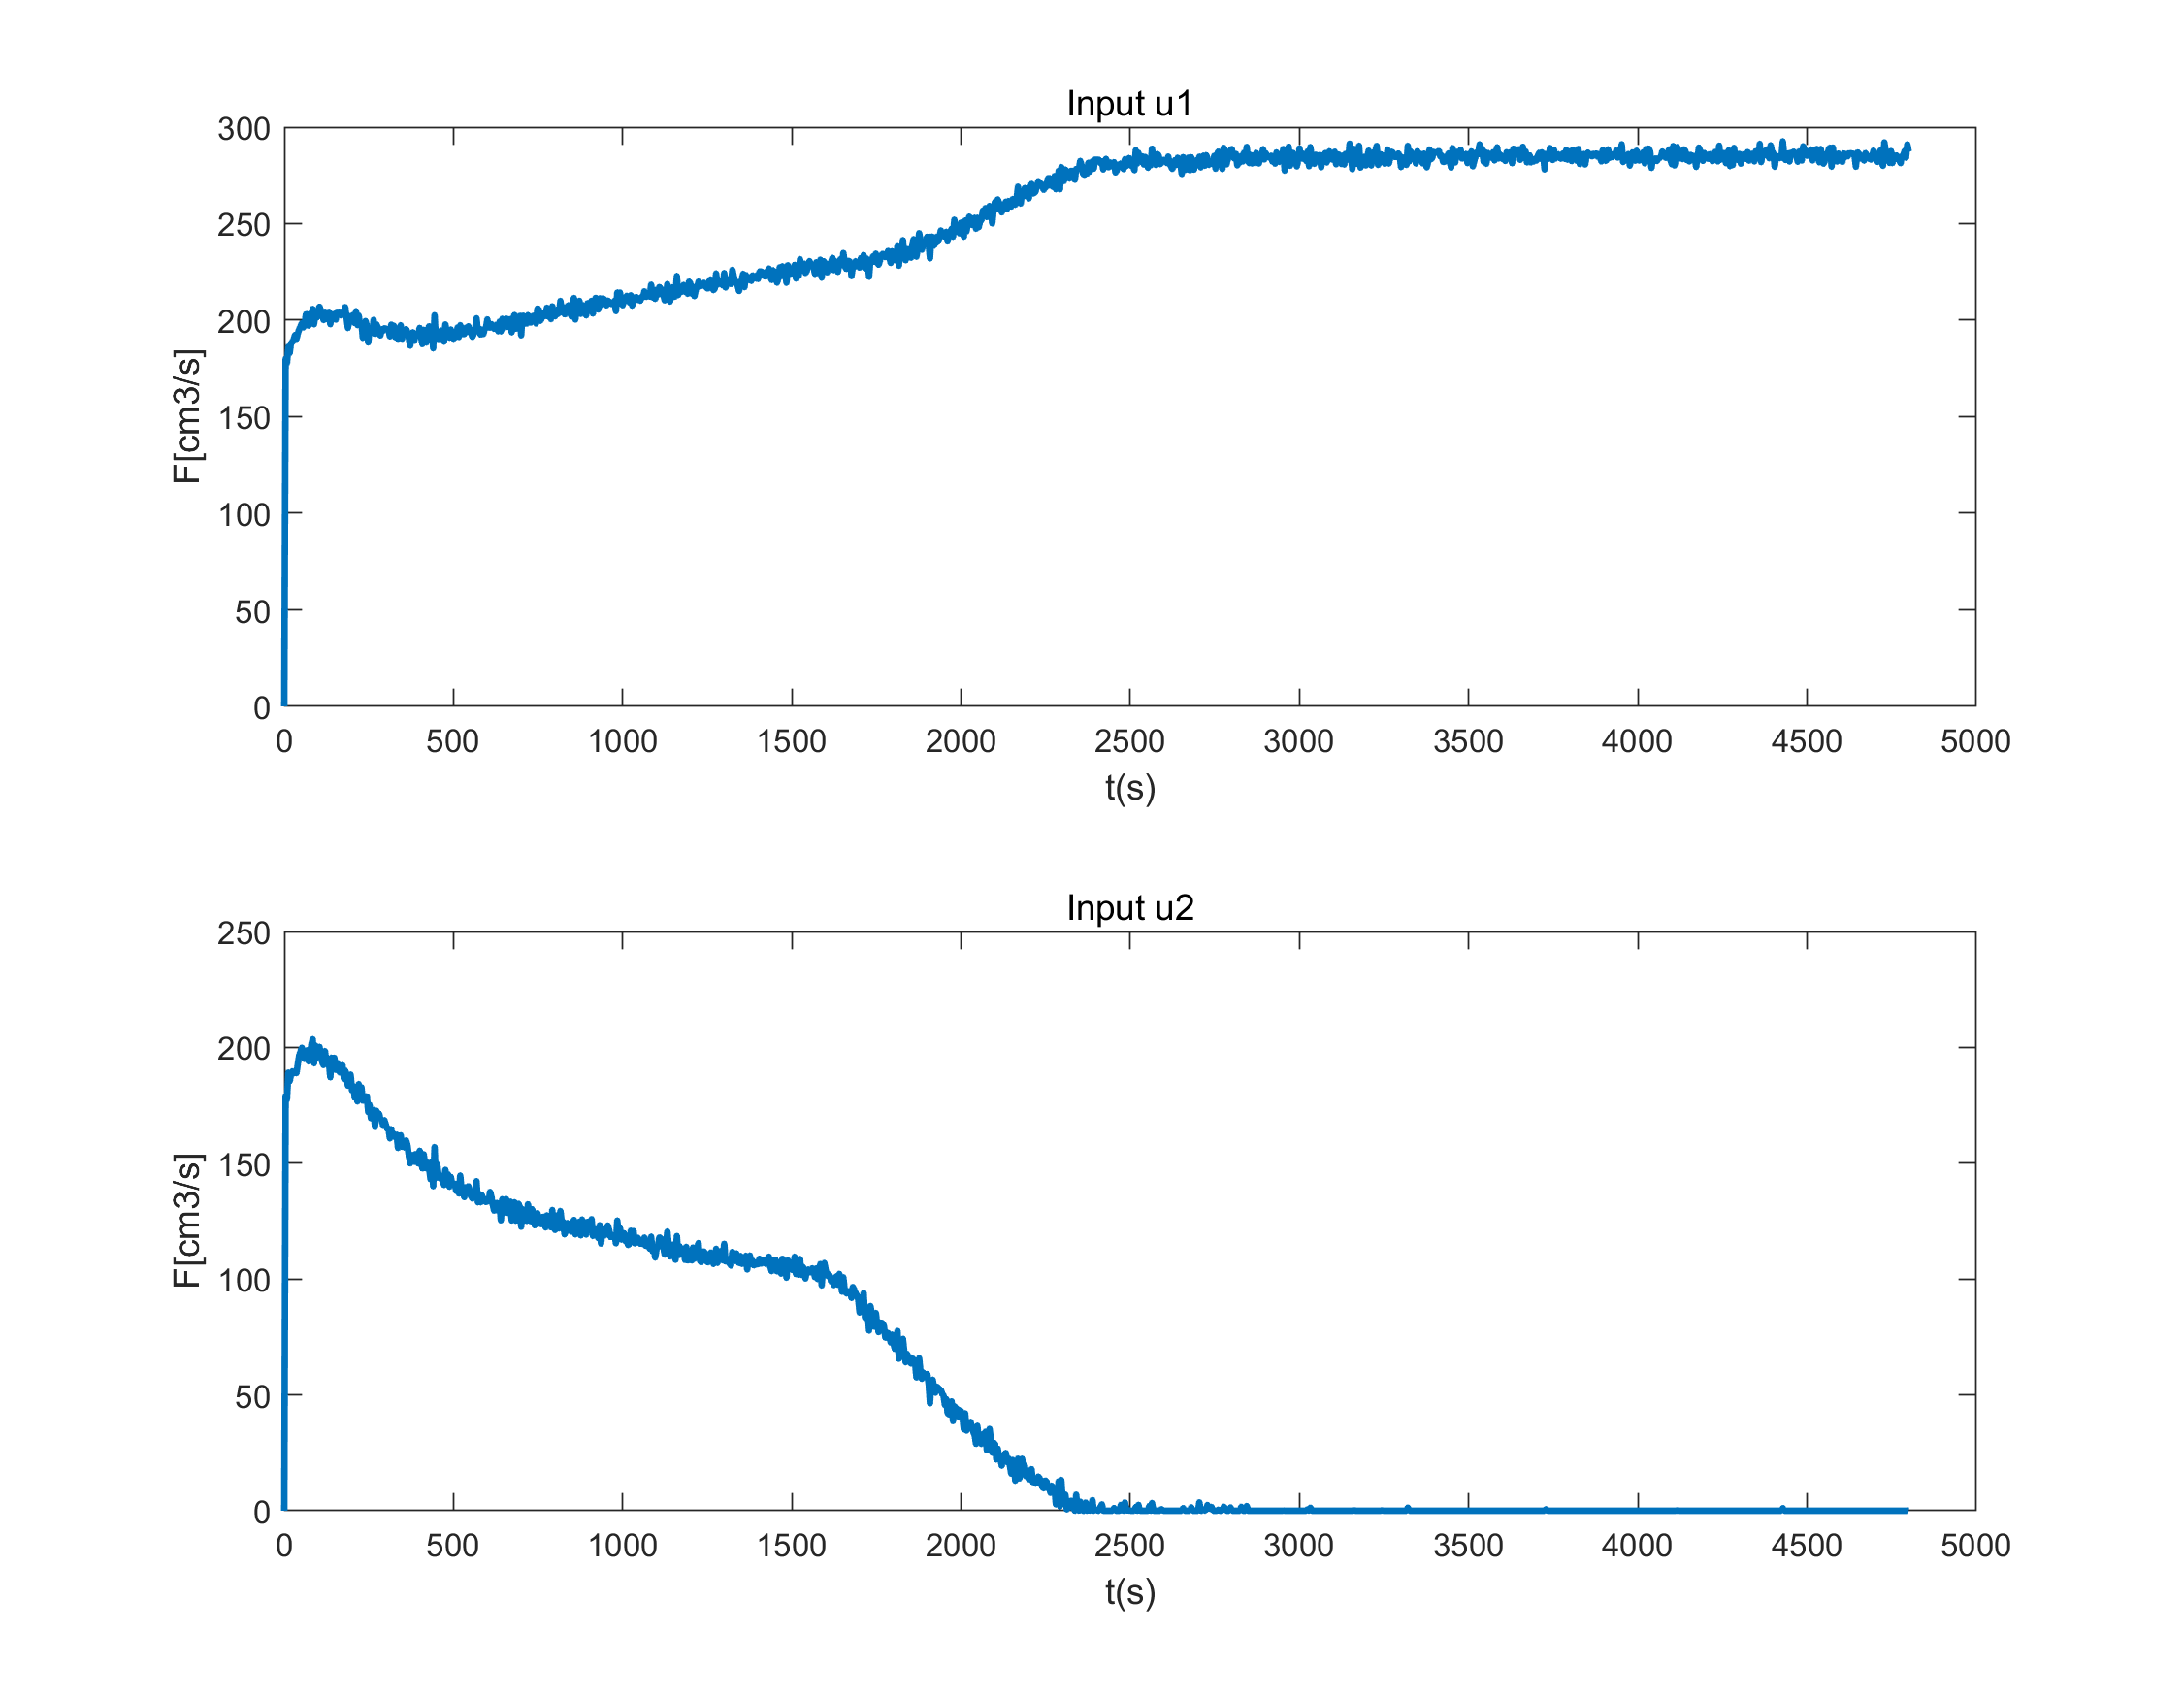

% ylim([0,20]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');

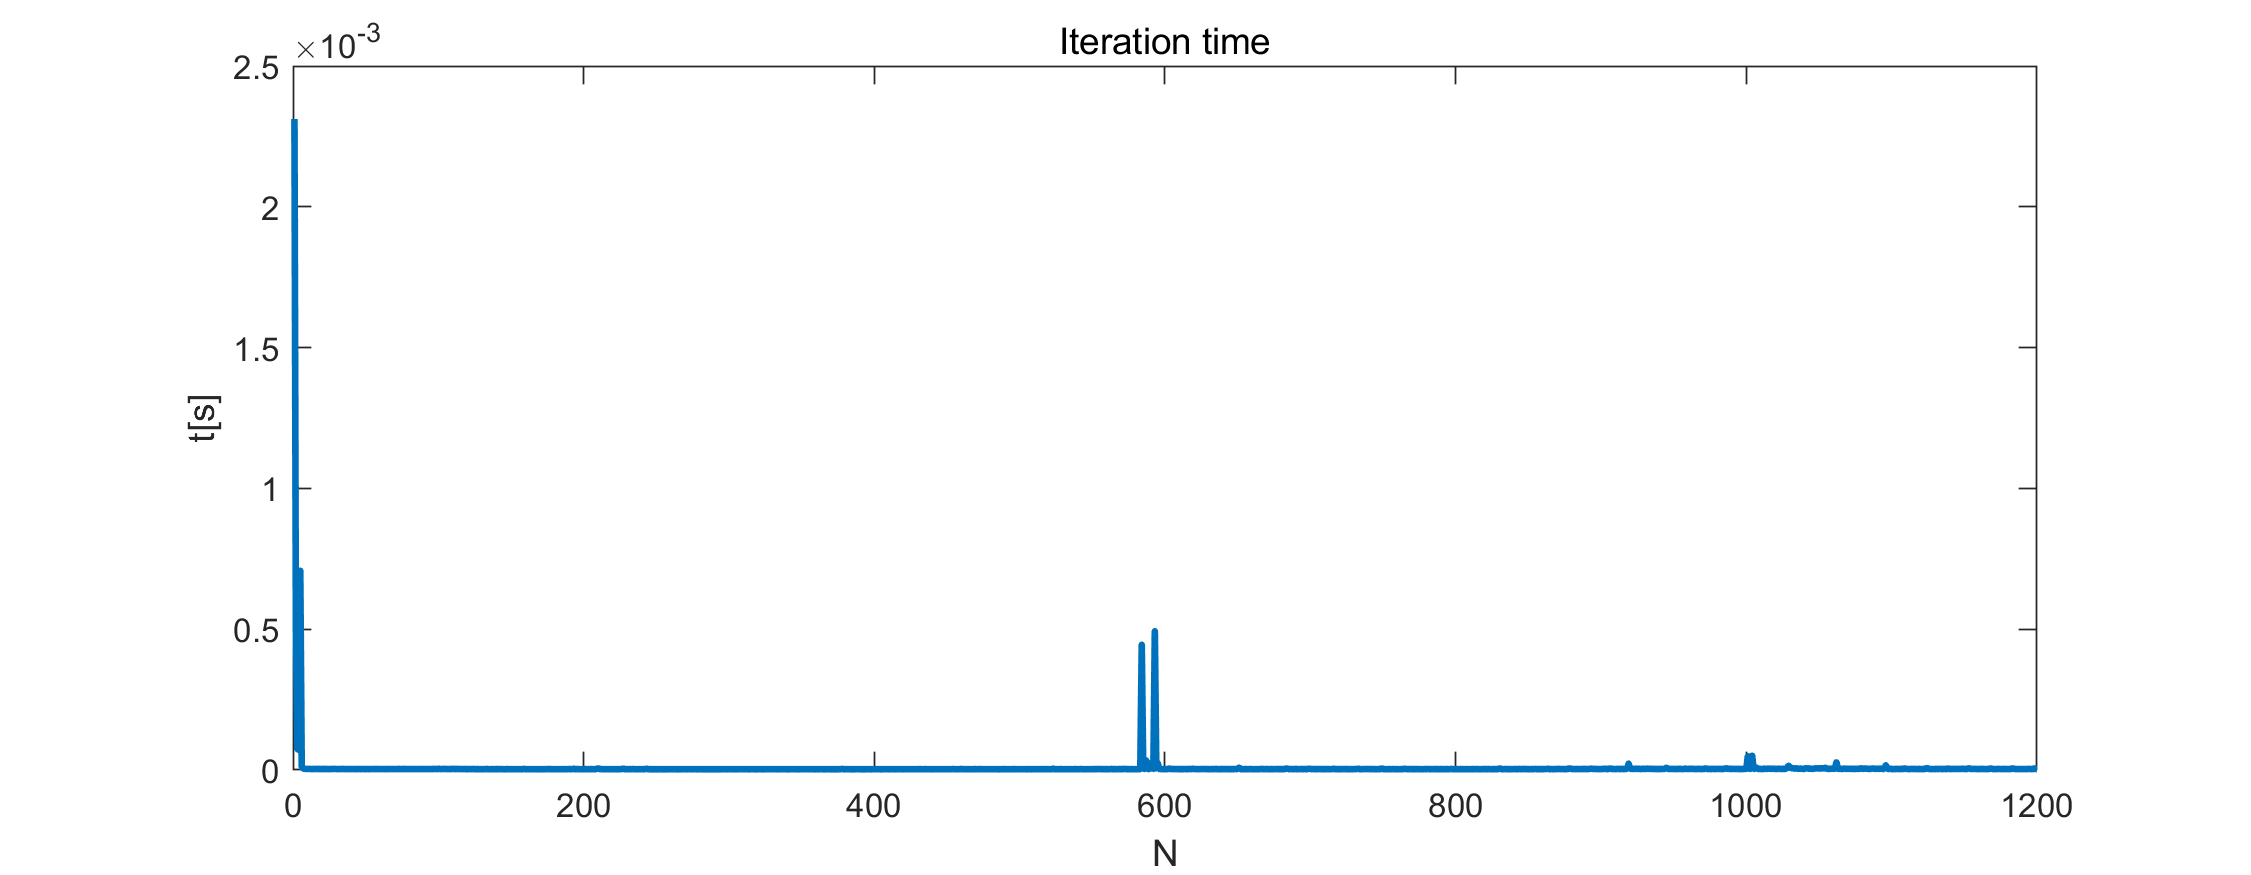

%ylim([0,40]);

figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');

%PID in nonlinear model without step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
d = [repmat(300,1,N); repmat(300,1,N)];
%d(1,index_step:end)=350;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);

x0=zeros(4,1);
d0=zeros(2,1);
x(:,1) = x0;
u(:,1) = zeros(2,1);
ref=200;

%PID
u_min=0;
u_max=1000;
uk=us;
xk=x0;
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
yk_old=yk;
Ik=0;
KP=2.2715;
KI=0.012046;
KD=4.4948;
decop=[0.0787,0.9213;0.9213,0.0787];
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function
y(:,k)=yk;
z(:,k)=zk;

%%%%%%%%%%%%%%%PID controller%%%%%%%%%%%%%% 
tic;
[uk,Ik] = MIMOPID(0,ref,yk(1:2),yk_old(1:2),Ik,KP,KI,KD,Ts,u_min,u_max,decop);
elapsedTime = toc;
t_record=[t_record;elapsedTime];
yk_old=yk;
%state update
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],u(:,k),d(:,k)+w(:,k),p);
xk=Xk(end,:)';


x(:,k+1)=xk;
u(:,k+1)=uk;
end
k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;


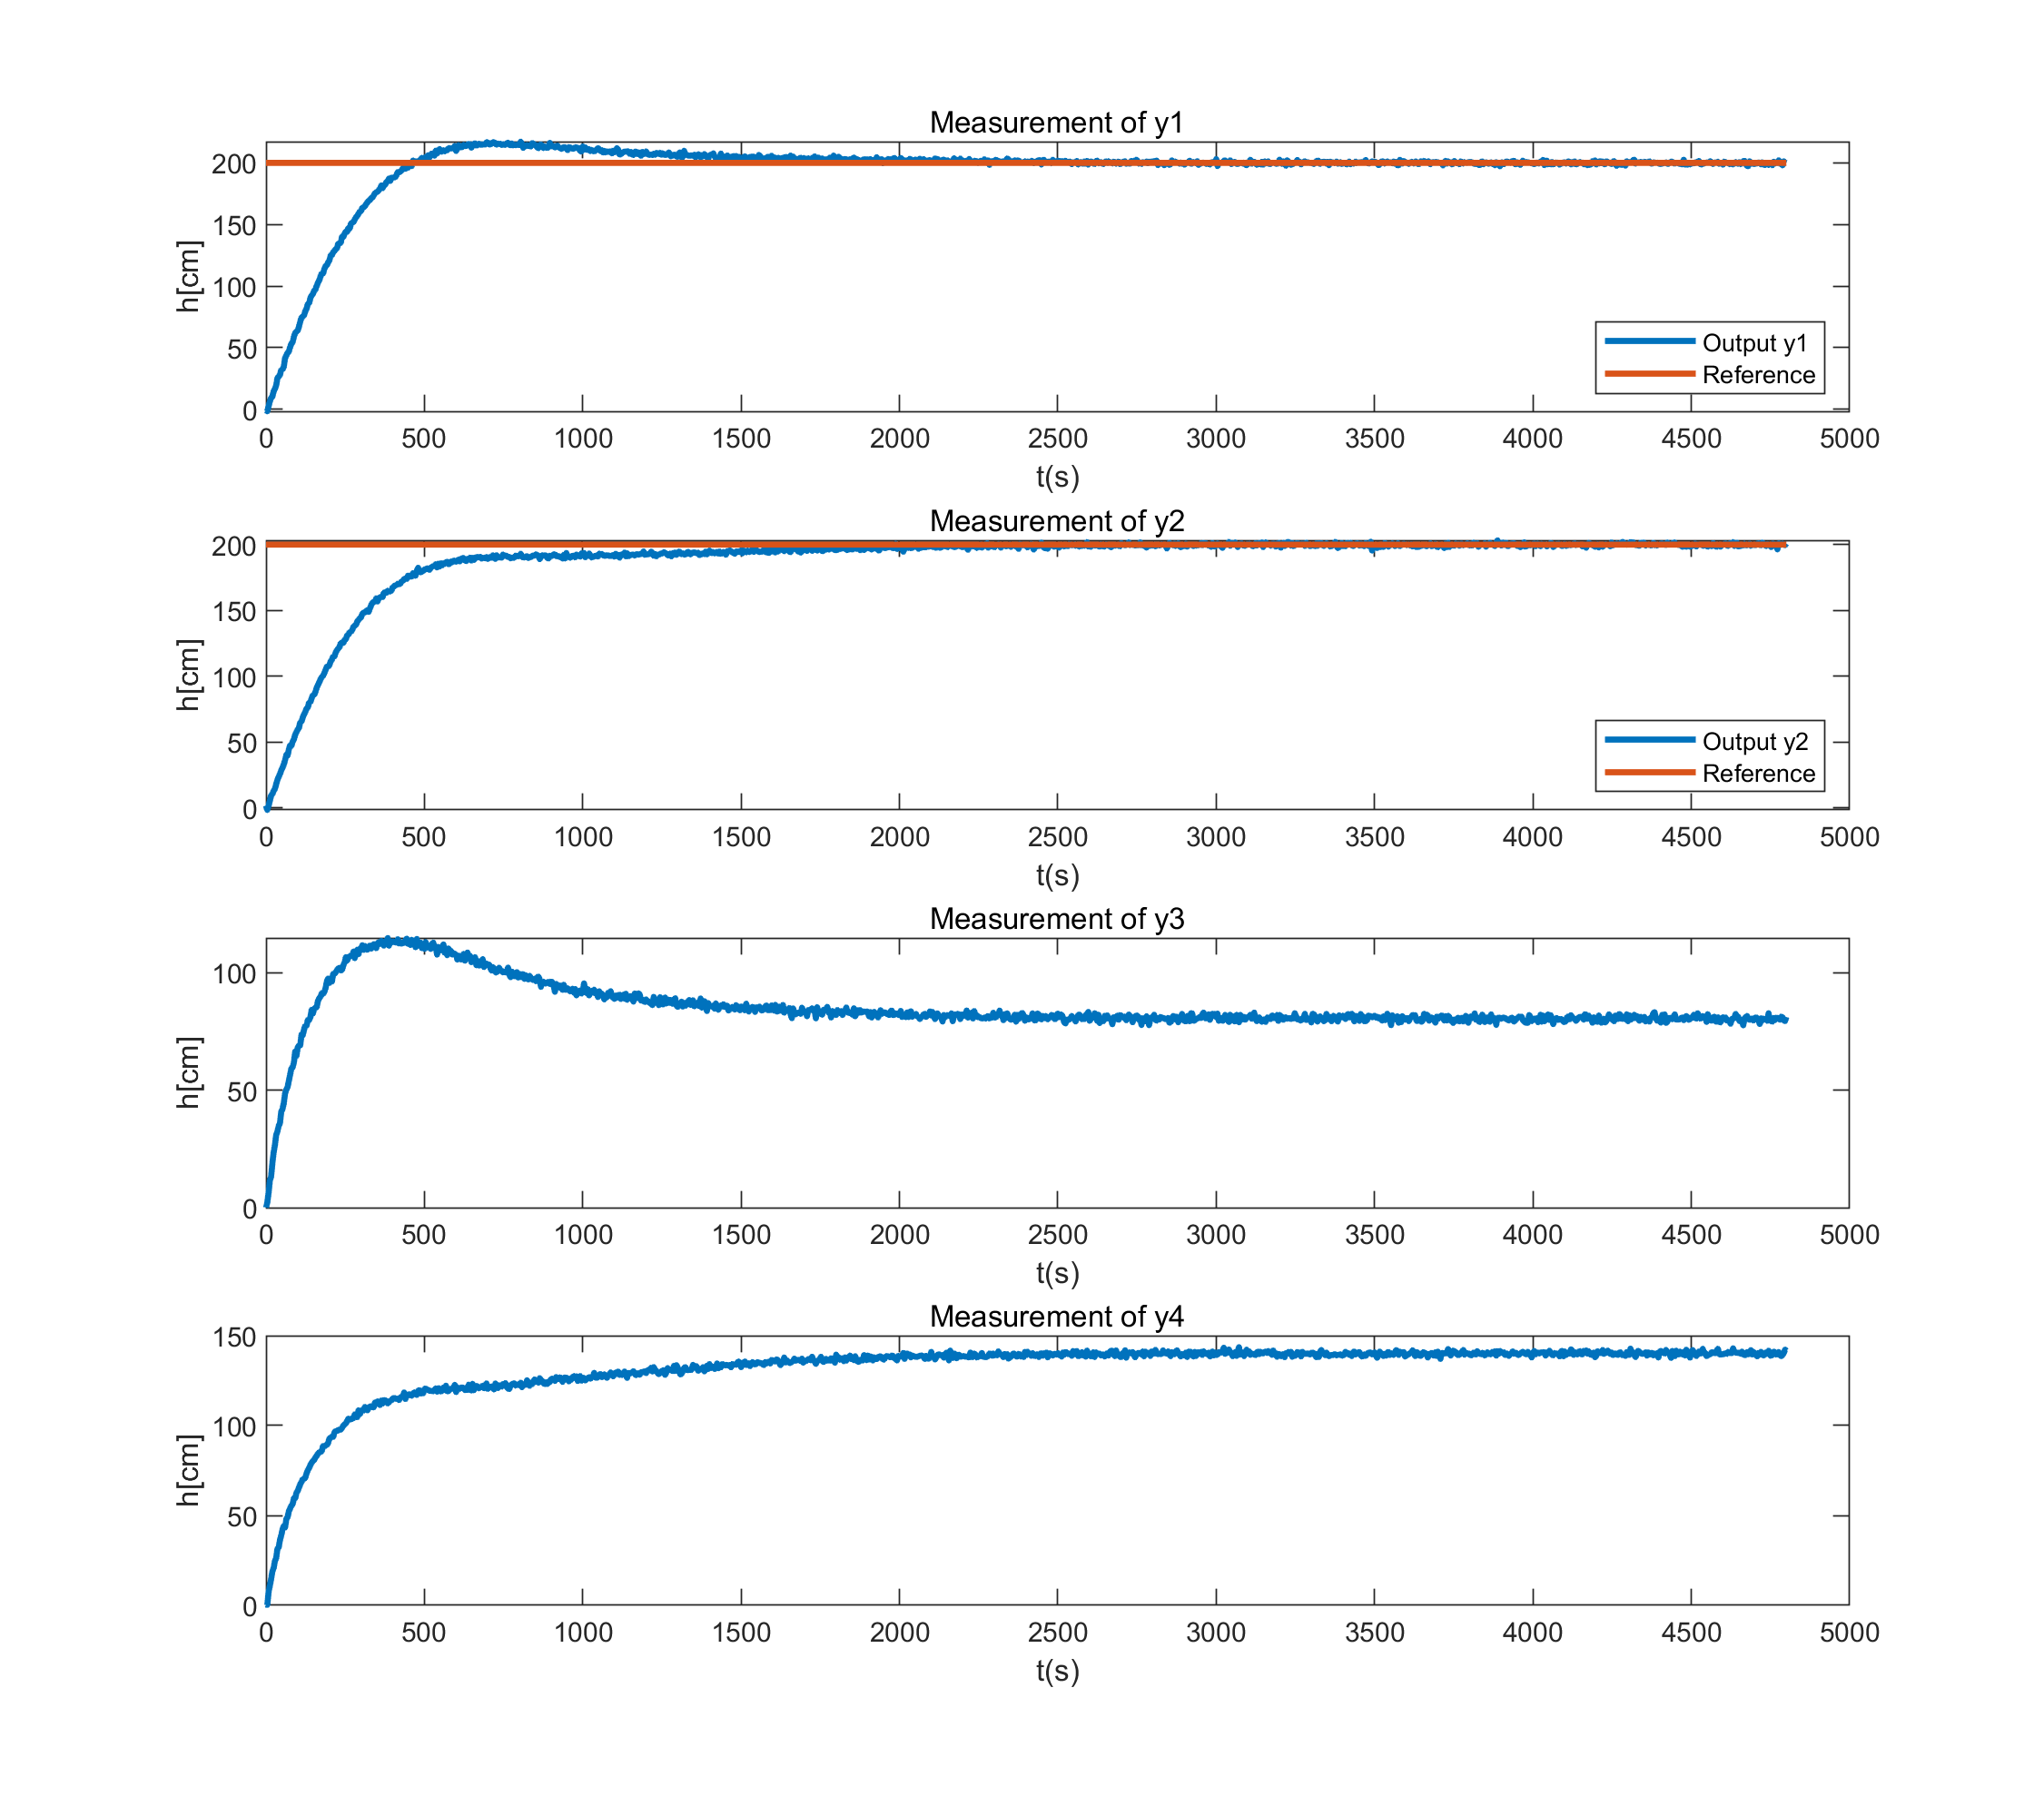

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');

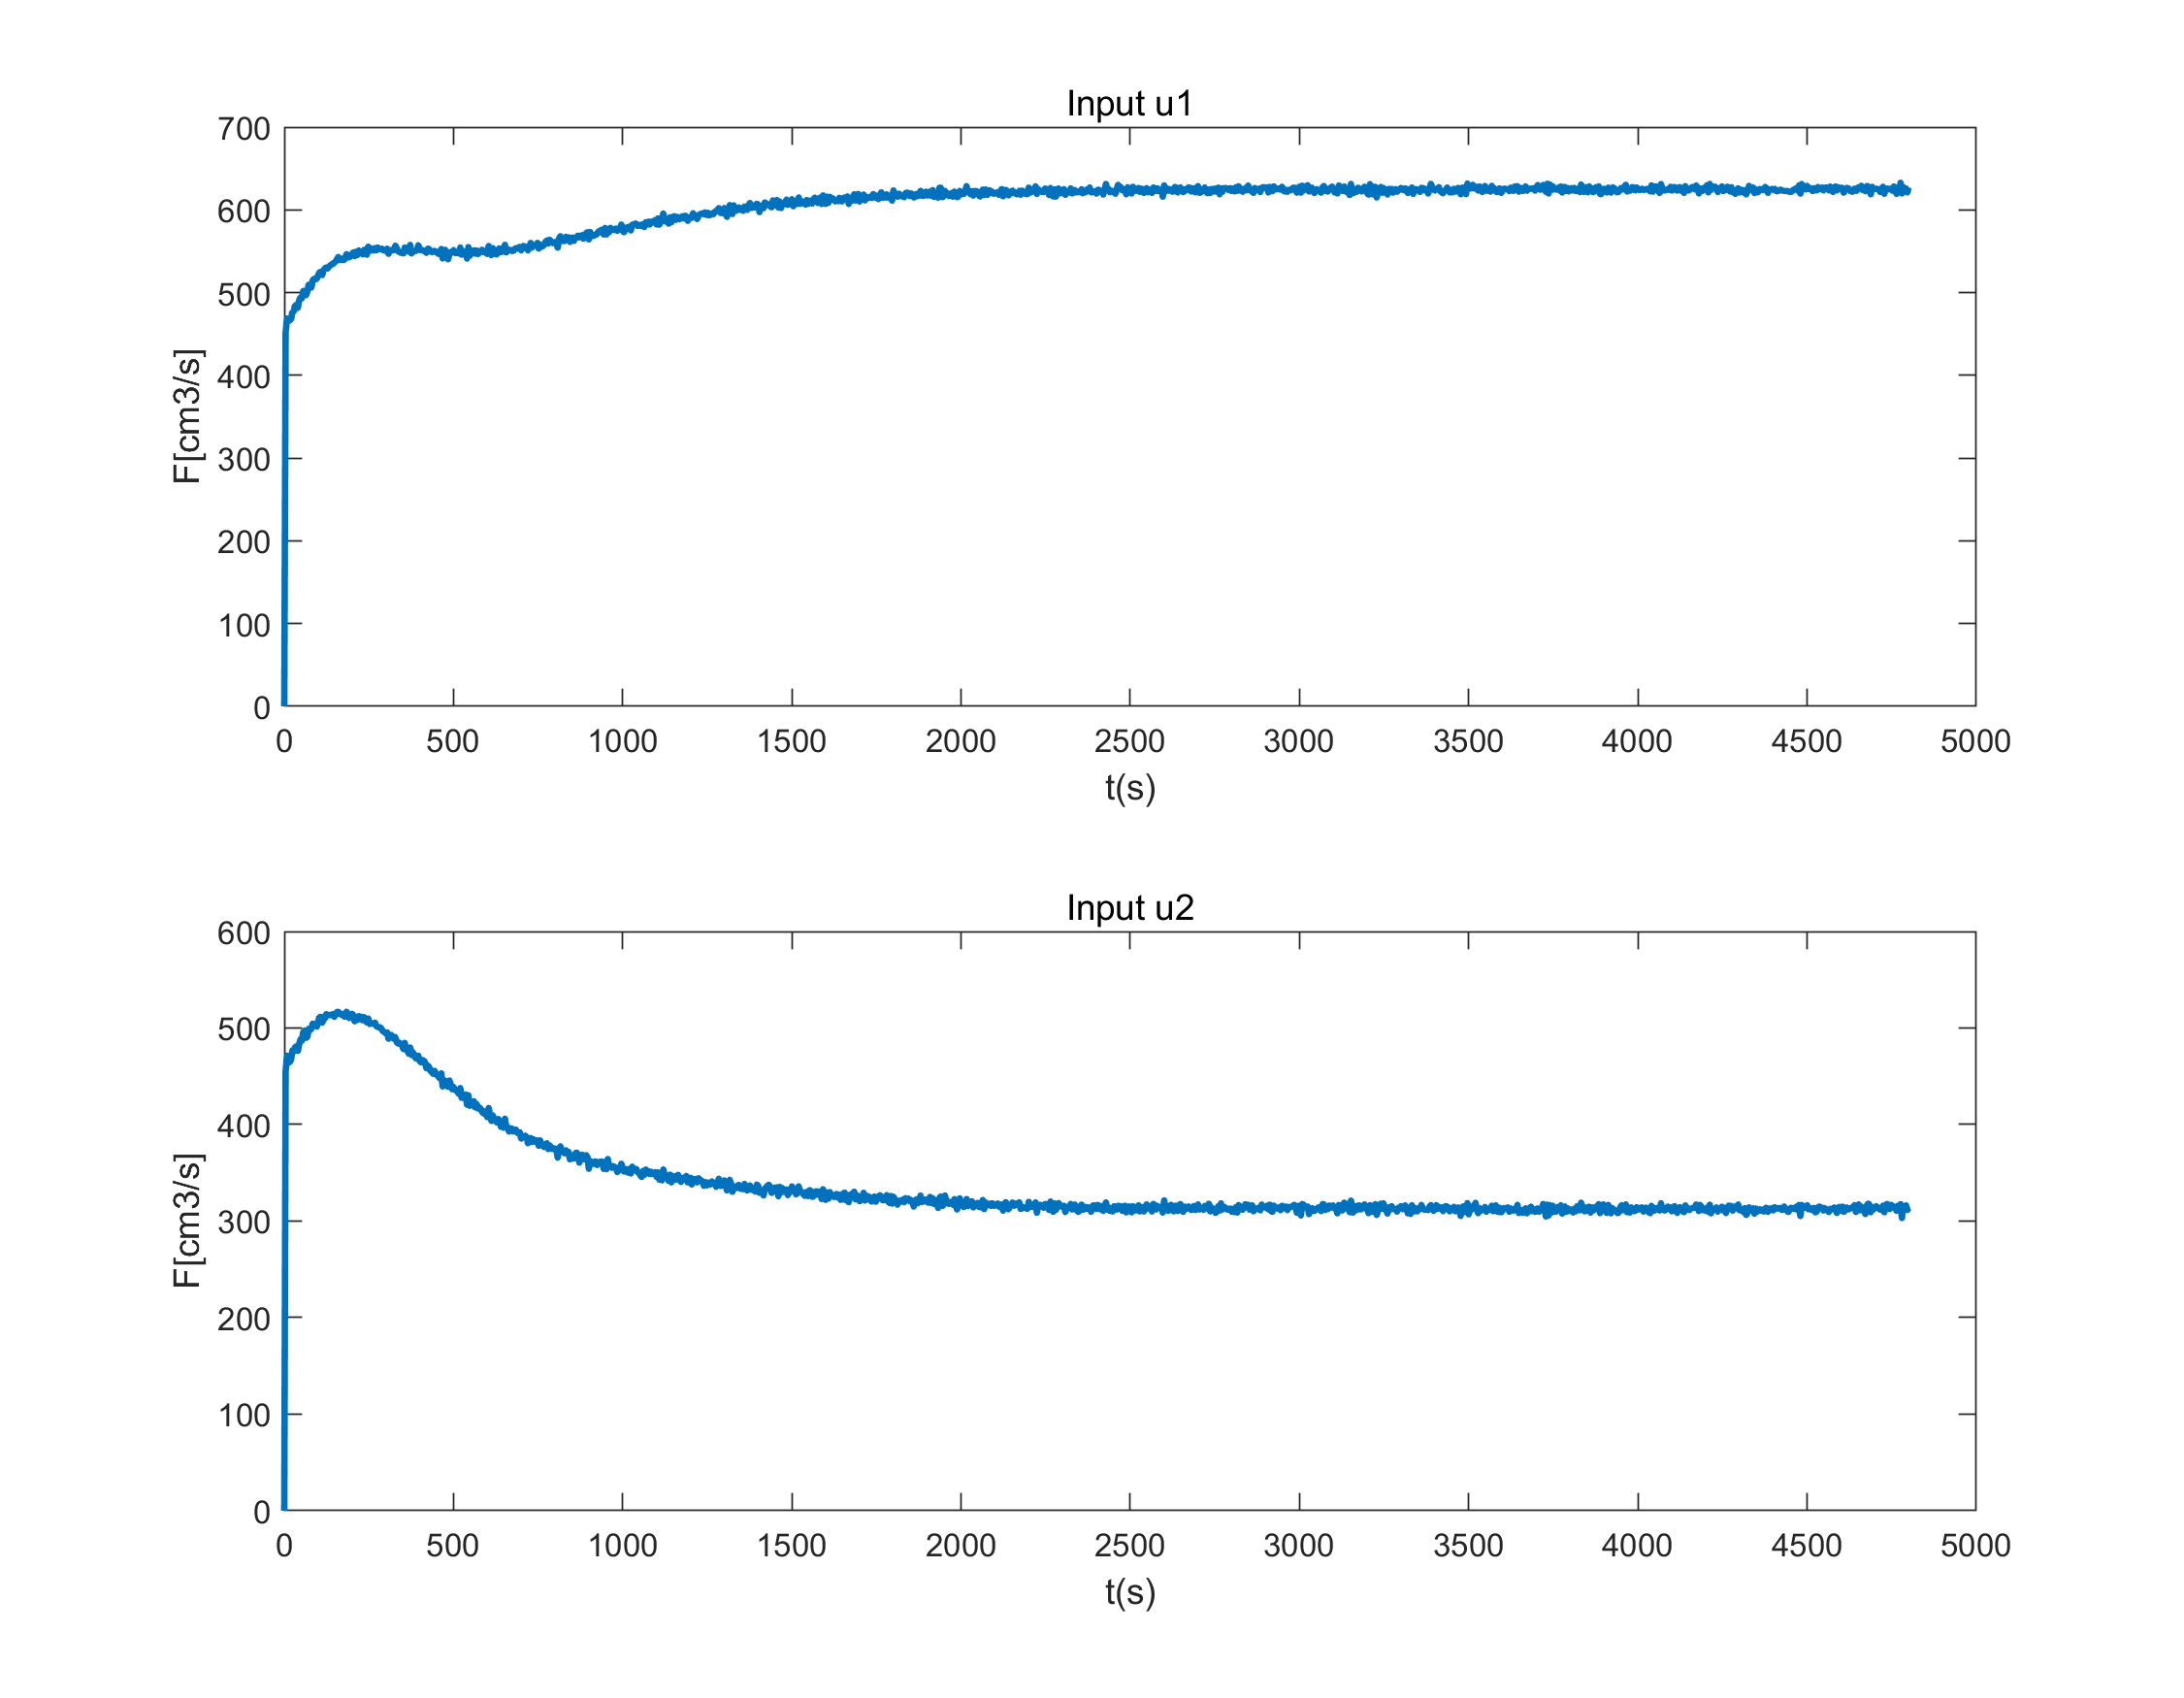

% ylim([0,20]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');

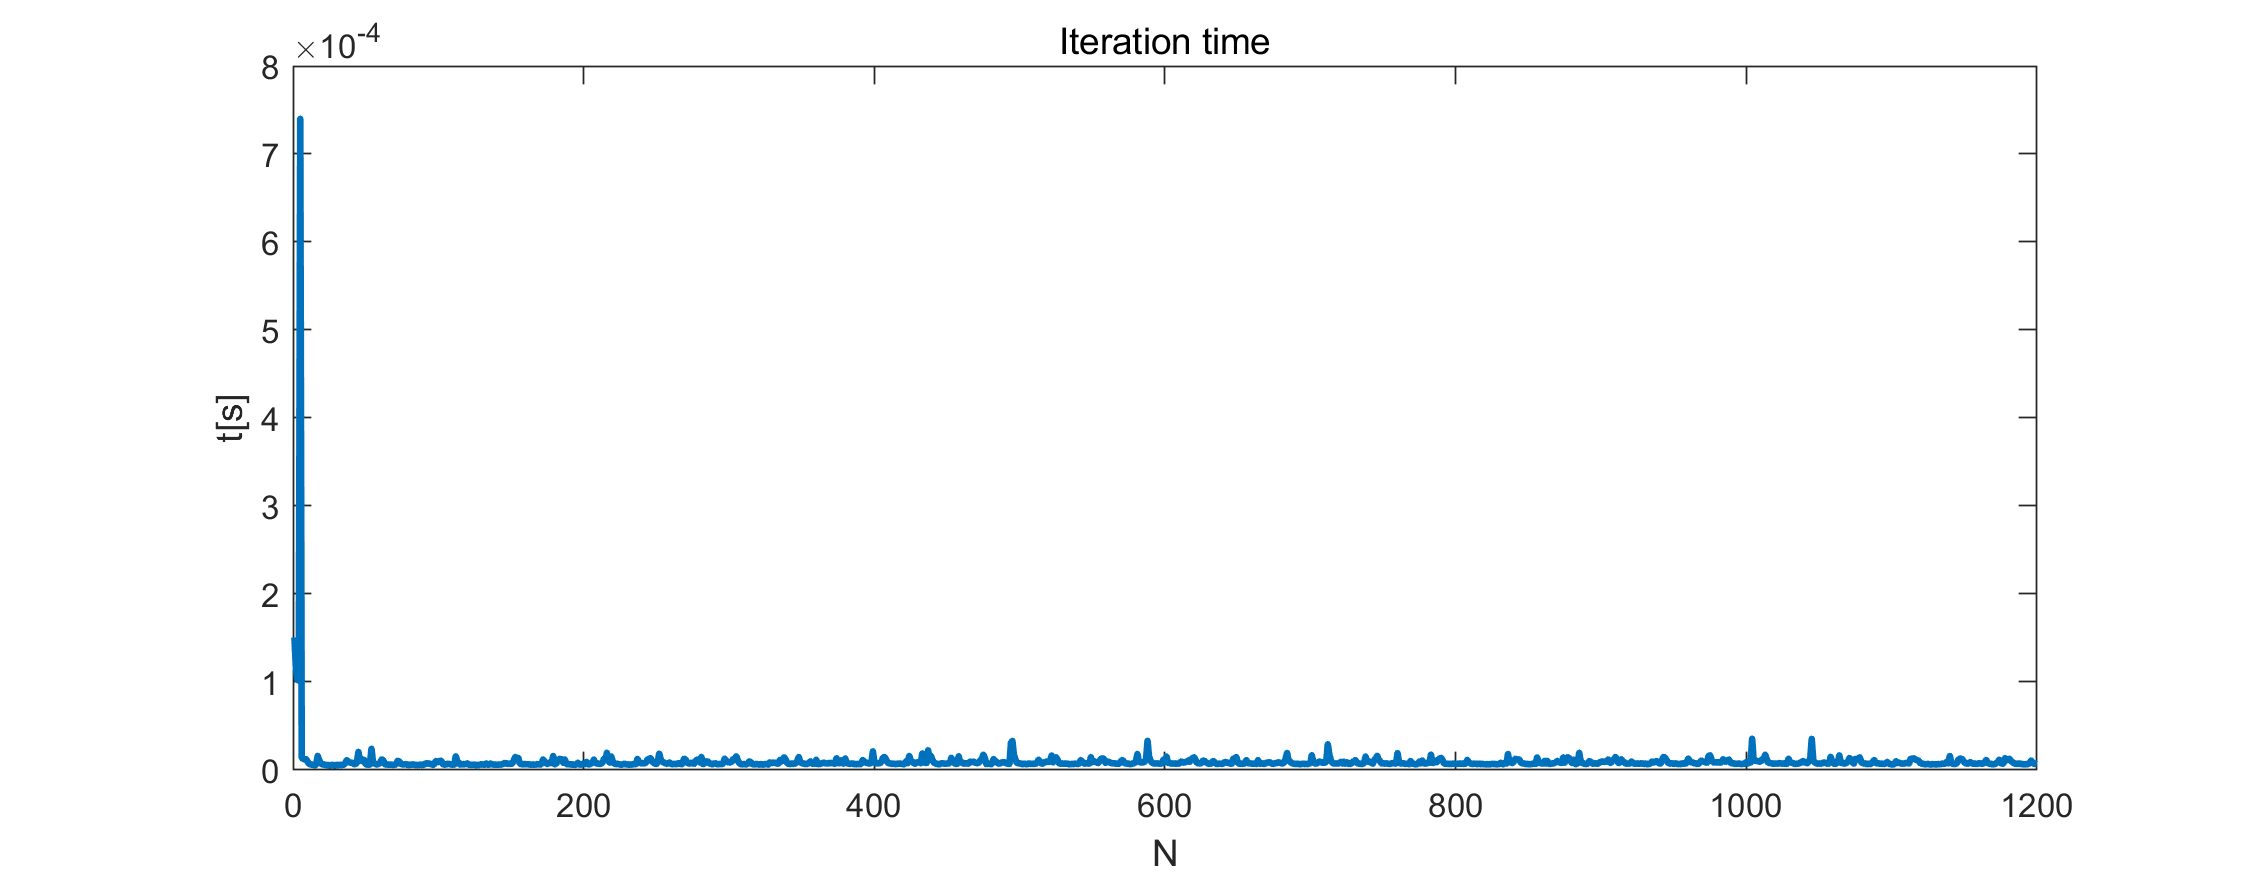

%ylim([0,40]);

figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');

%PID in nonlinear model with step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
d = [repmat(300,1,N); repmat(300,1,N)];
d(1,index_step:end)=350;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);

x0=zeros(4,1);
d0=zeros(2,1);
x(:,1) = x0;
u(:,1) = zeros(2,1);
ref=200;

%PID
u_min=0;
u_max=1000;
uk=us;
xk=x0;
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
yk_old=yk;
Ik=0;
KP=2.2715;
KI=0.012046;
KD=4.4948;
decop=[0.0787,0.9213;0.9213,0.0787];
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function
y(:,k)=yk;
z(:,k)=zk;

%%%%%%%%%%%%%%%PID controller%%%%%%%%%%%%%% 
tic;
[uk,Ik] = MIMOPID(0,ref,yk(1:2),yk_old(1:2),Ik,KP,KI,KD,Ts,u_min,u_max,decop);
elapsedTime = toc;
t_record=[t_record;elapsedTime];
yk_old=yk;
%state update
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],u(:,k),d(:,k)+w(:,k),p);
xk=Xk(end,:)';


x(:,k+1)=xk;
u(:,k+1)=uk;
end
k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;


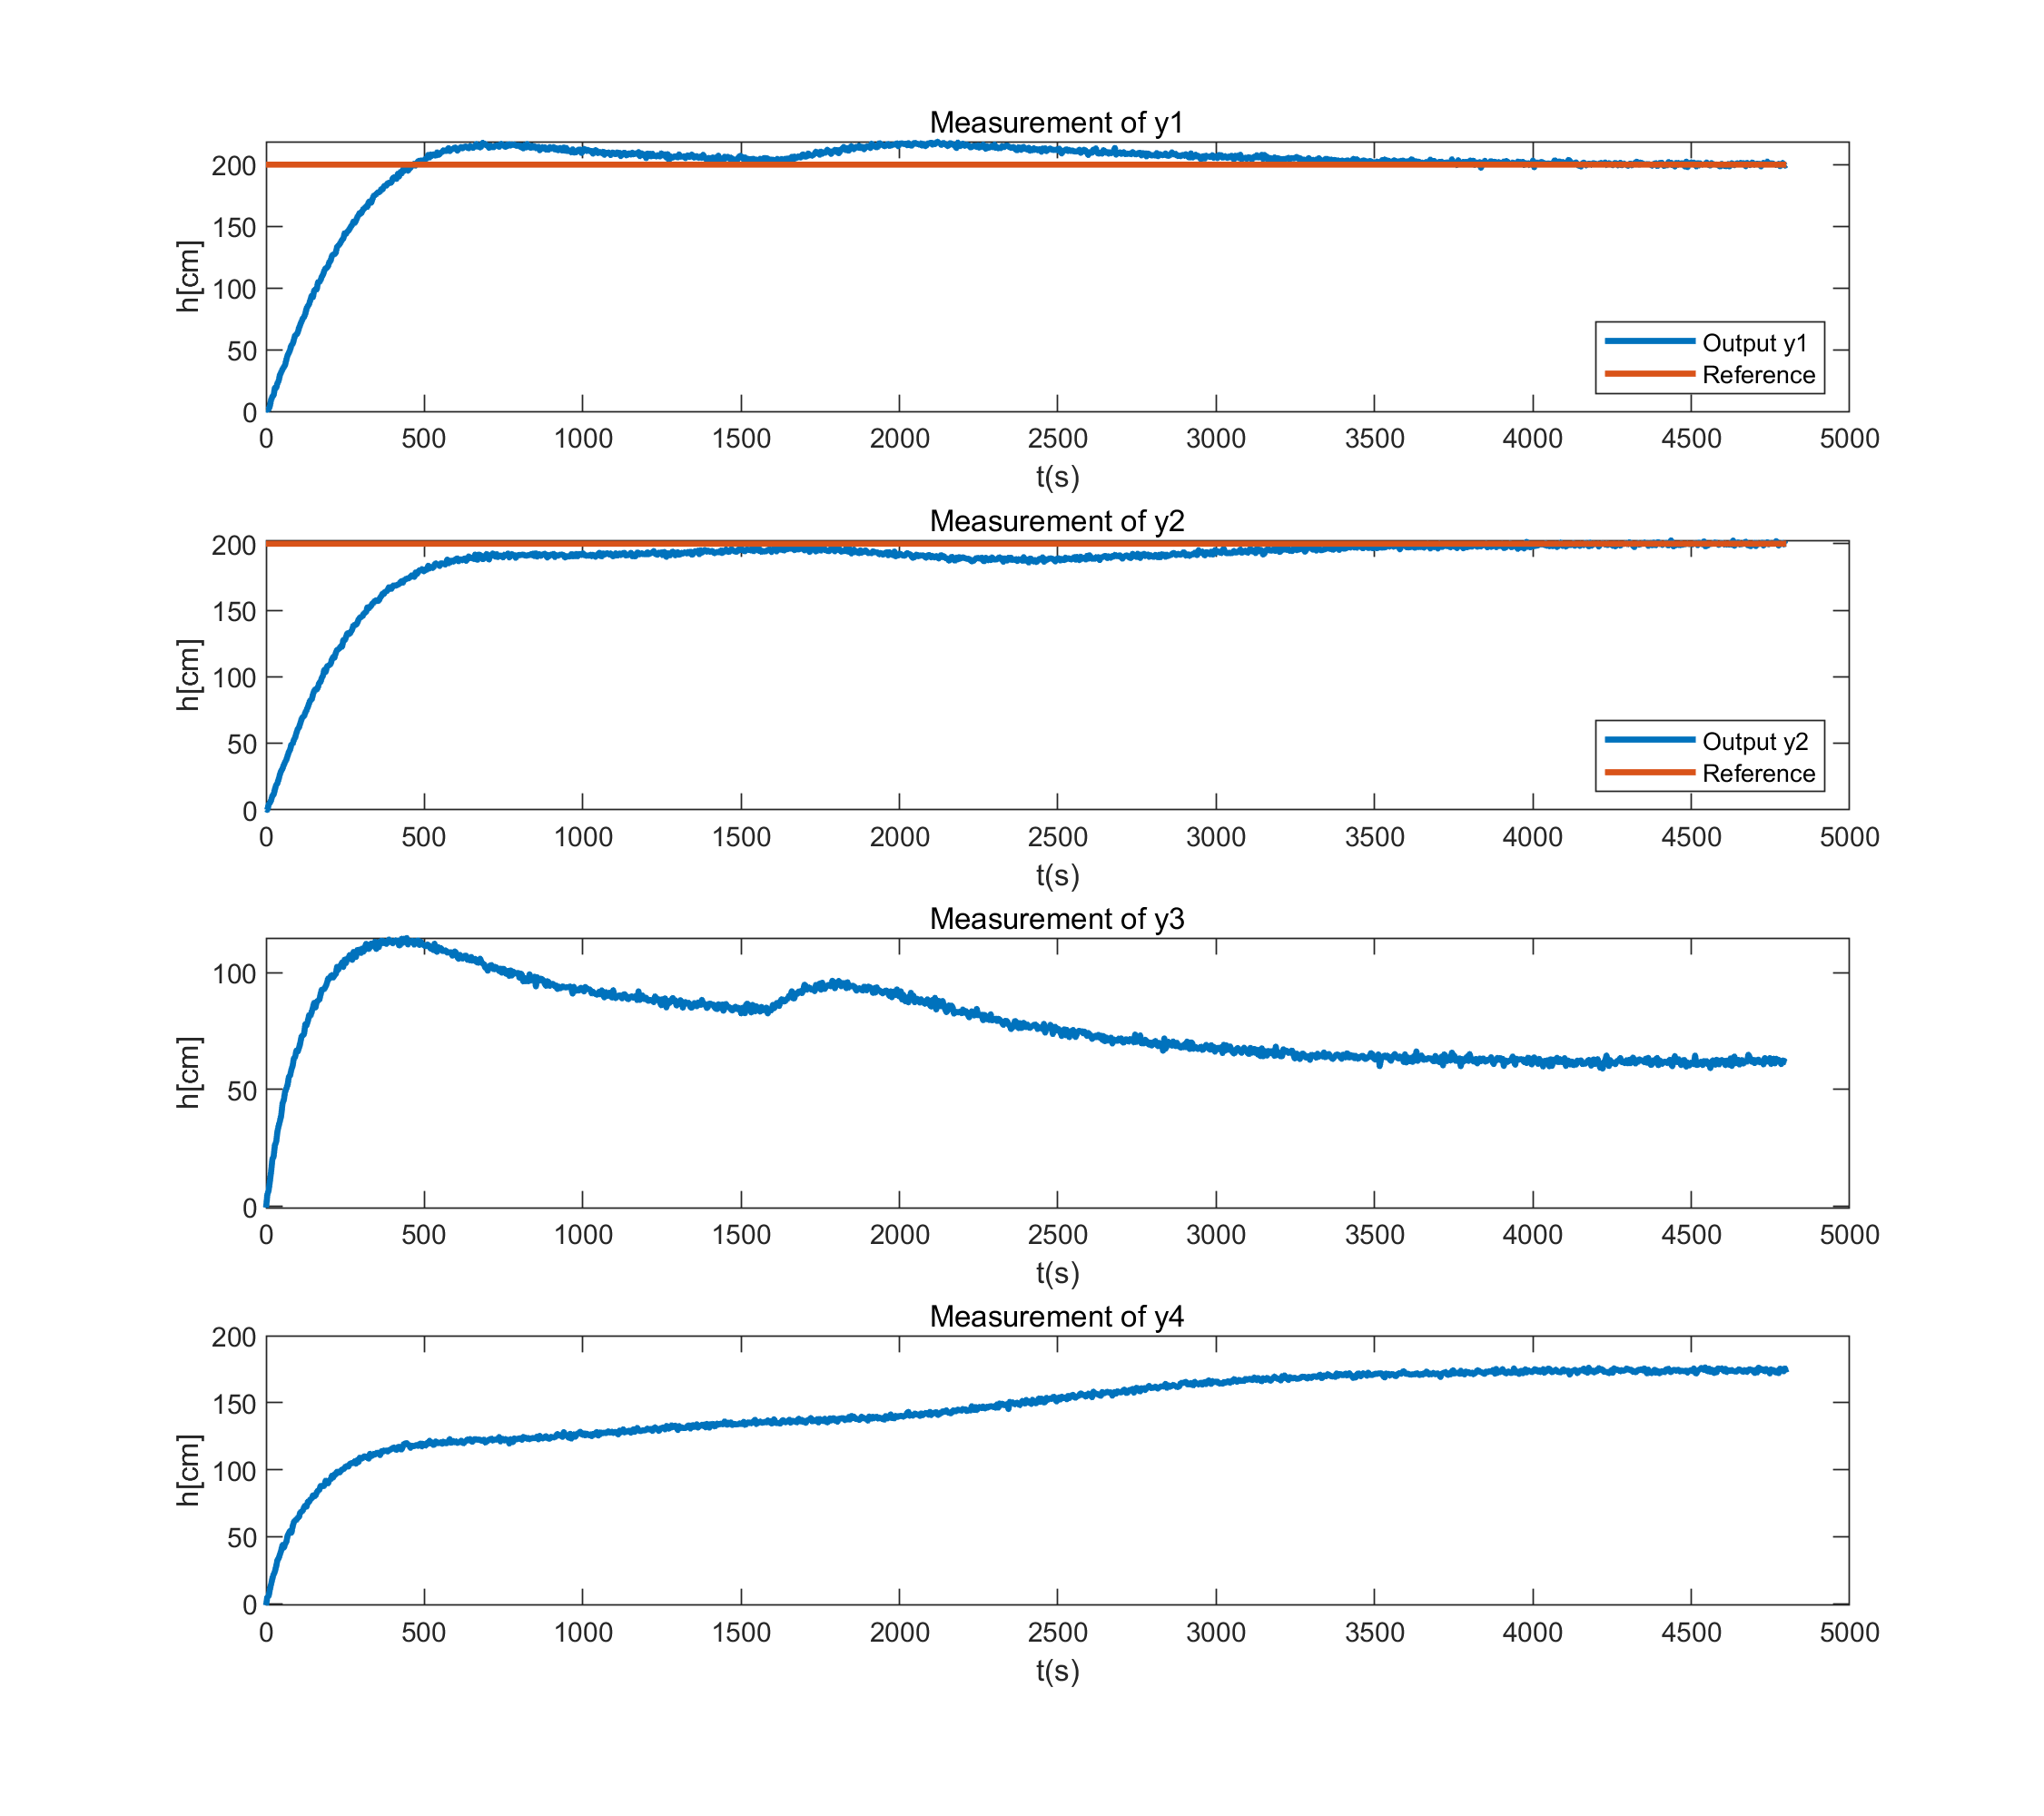

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'Southeast');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');

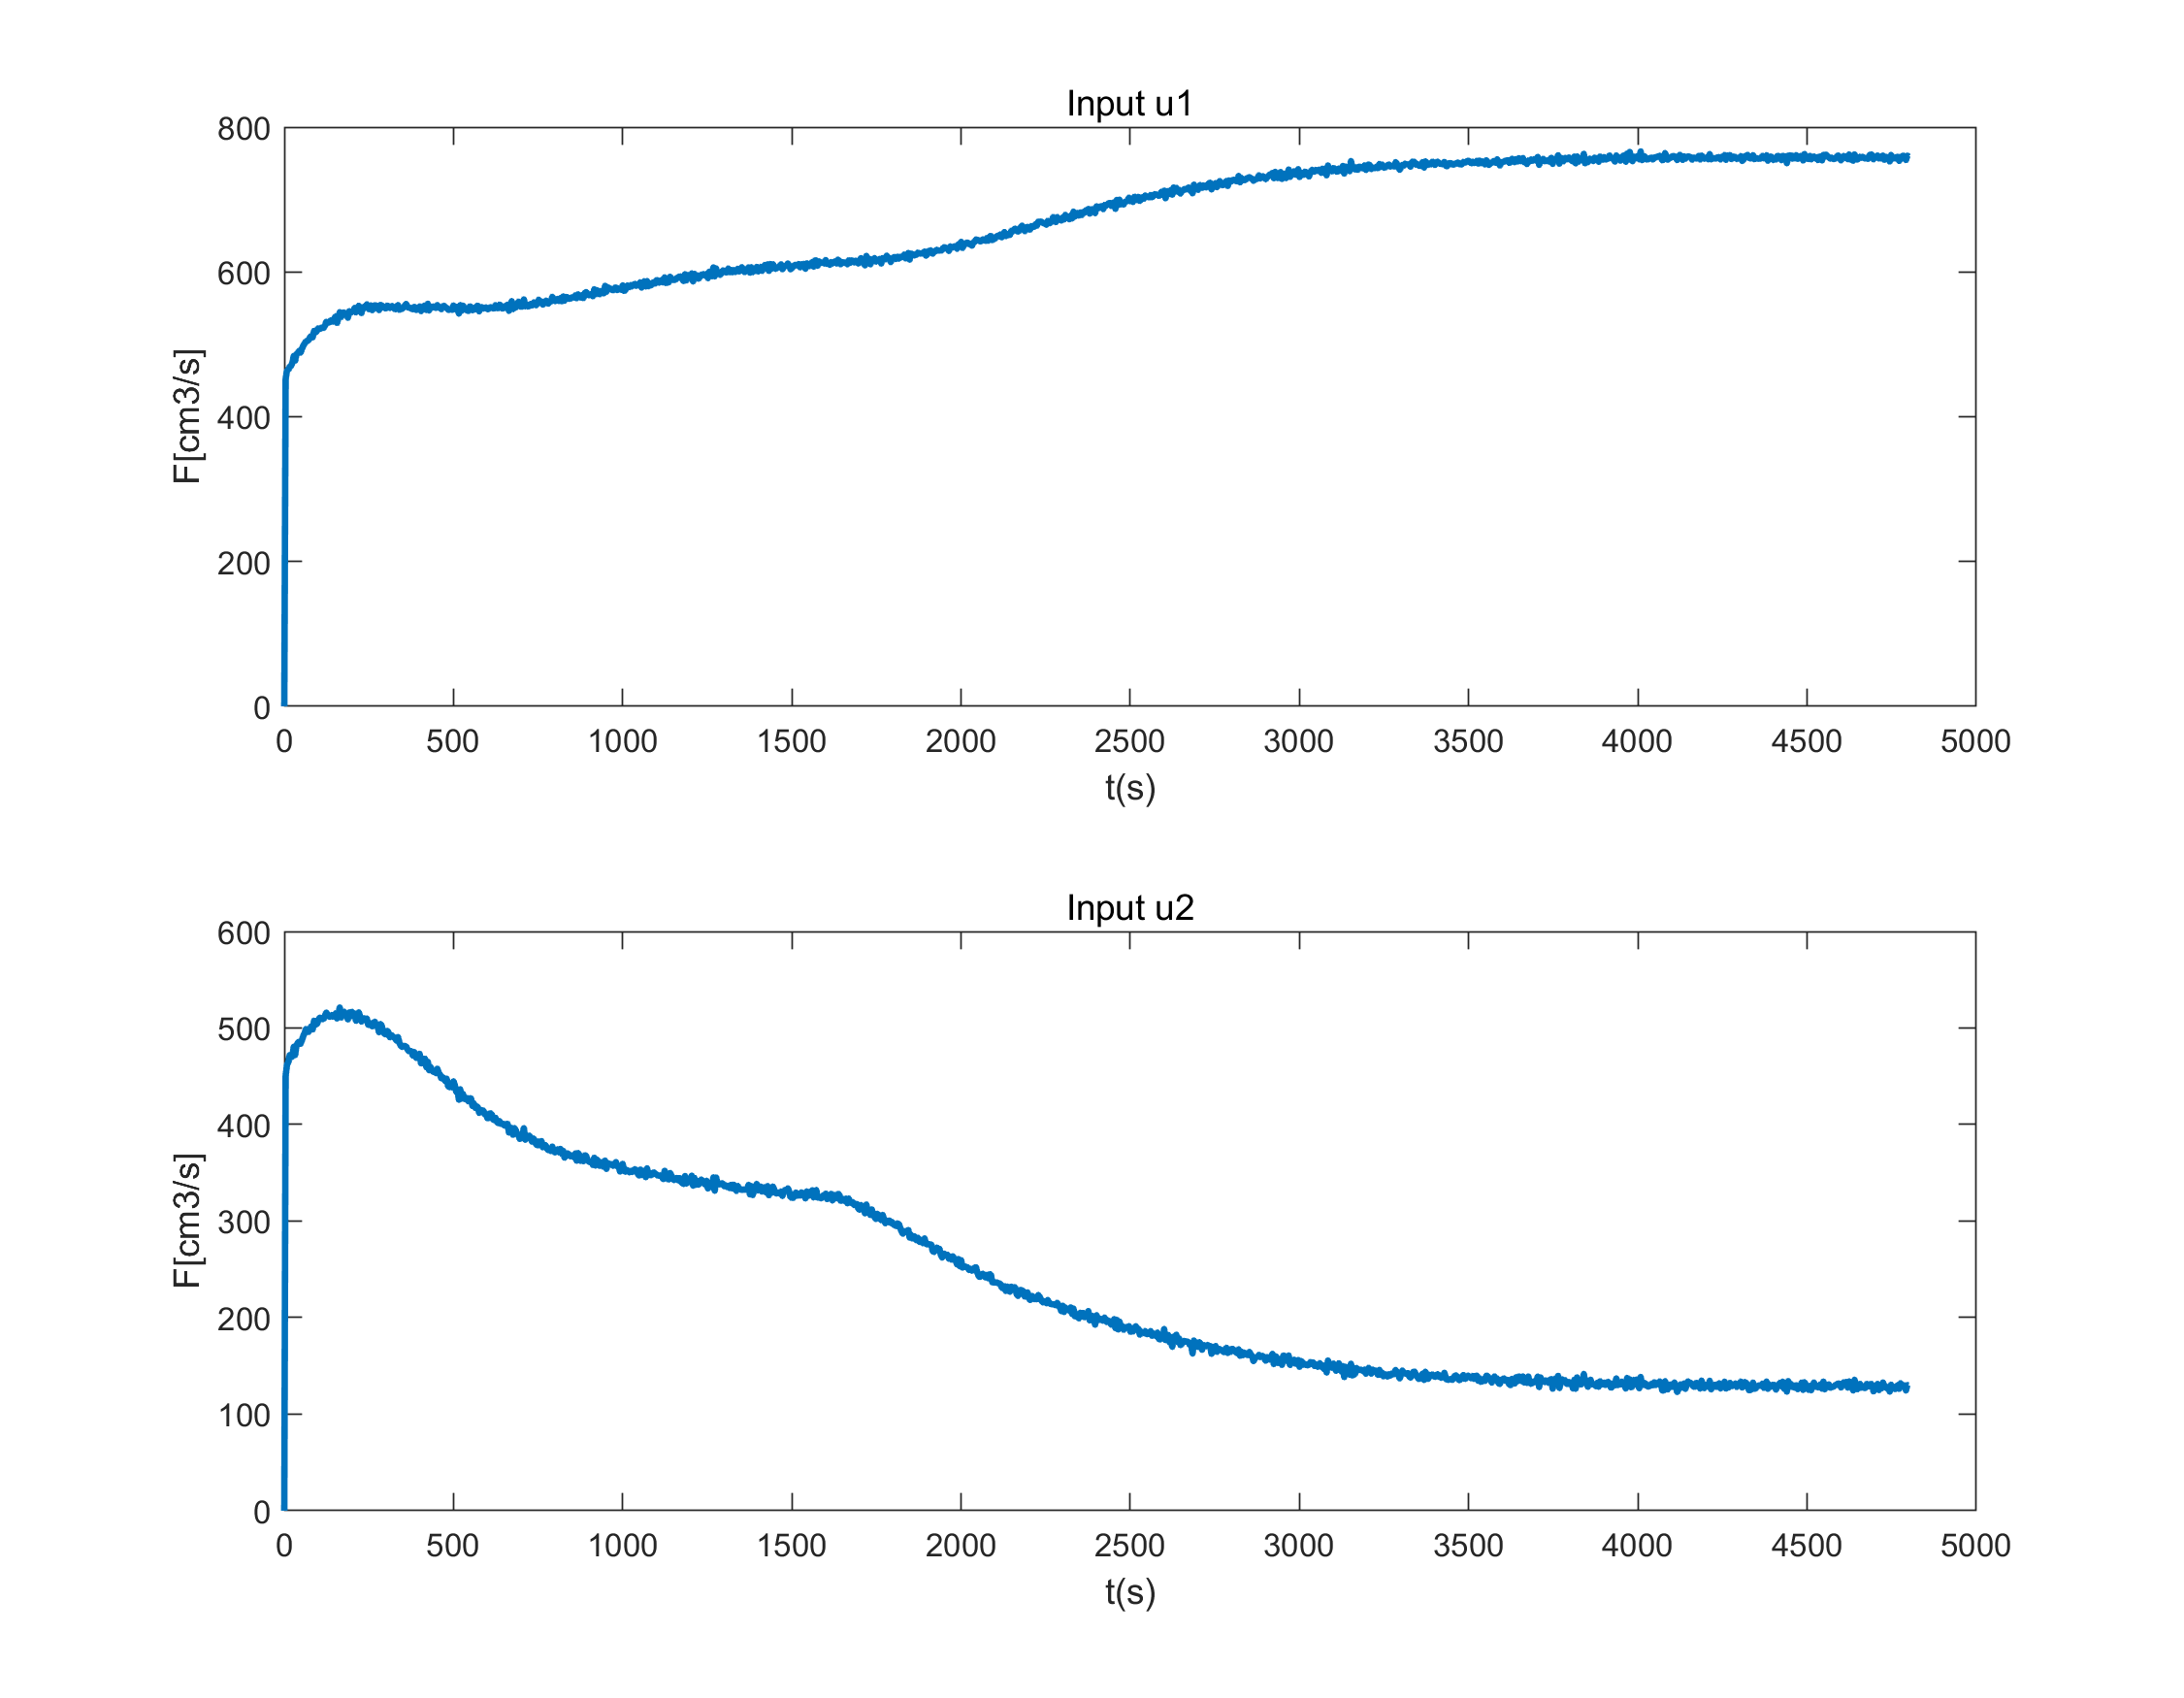

% ylim([0,20]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');

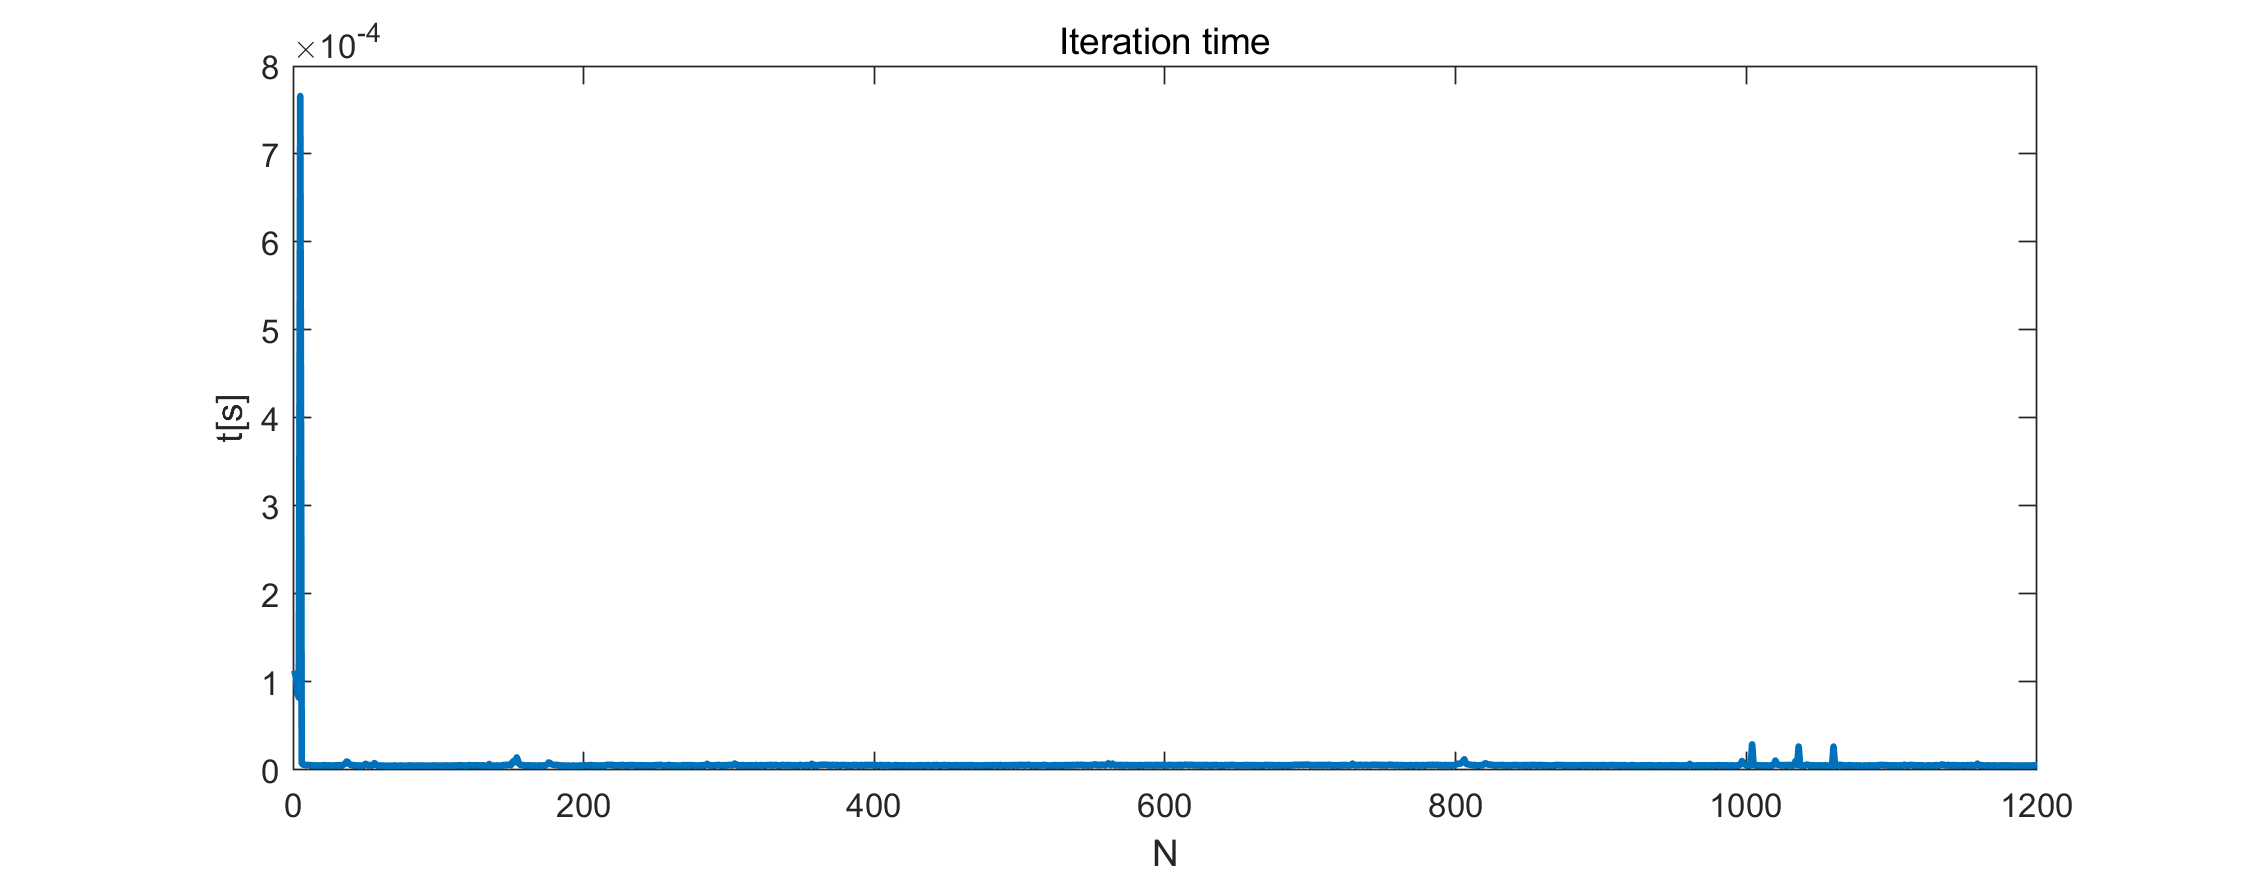

%ylim([0,40]);

figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');